# Project2：Basic Principle of OFDM Technology

# 基于OFDM技术的无线信道传输

#### 组员： 12011708杨成博 12010502陈逸飞

## 1. Abstract

- OFDM principle

- Design and Analysis

- Simulations of OFDM system

- Conclusion

- Discussions

- Code

## 2.OFDM principle

正交频分复用（OFDM）技术与已经普遍应用的频分复用（FDM，Frequency  Division Multiplexing）技术十分相似。与 FDM 基本原理相同，OFDM 把高速的数据流通过串/并变换，分配到速率相对较低的若干个频率子信道中进行传输，不同的是，OFDM 技术更好地利用了控制方法，使频谱利用率有所提高。

## 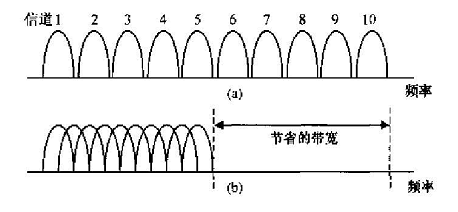

### (a)流程介绍

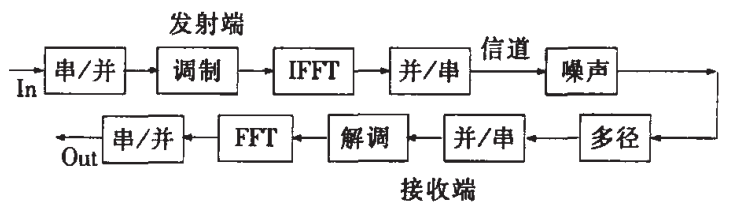

    OFDM 技术的主要思想是将指配的信道分成许多正交子信道，在每个子信道上进行窄带调制和传输，信号带宽小于信道的相关带宽。OFDM 单个用户的信息流被串/并变换为多个低速率码流(100Hz-50kHz)，每个码流用一条载波发送。OFDM 采用跳频方式选用即便频谱混叠也能保持正交的波形，所以 OFDM 既有调制技术，也有复用技术。OFDM 增强了抗频率选择性衰落和抗窄带干扰的能力。在单载波系统中，单个衰落或干扰会导致整条链路不可用，但在多载波系统中， 只会有一小部分载波受影响。纠错码的应用可以恢复一些易错载波上的信息。

    OFDM允许各载波间频率互相混叠，采用基于载波频率正交的FFT调制，由于各个载波的中心频点处没有其他载波的频谱分量，所以能够实现各个载波的正交。不通过很多带通滤波器来实现，而是直接在基带处理，这也是OFDM有别于其他系统的优点之一。OFDM的接收机实际上是一组解调器，它将不同载波搬移至零频，在一个码元周期内积分，其他载波由于与所积分的信号正交，不会对这个积分结果产生影响。OFDM的高数据速率与子载波的数量有关，增加子载波数目能提高数据的传送速率。OFDM每个频带的调制方法可以不同，增加了系统的灵活性，OFDM适用于多用户的高灵活度、高利用率的通信系统

## 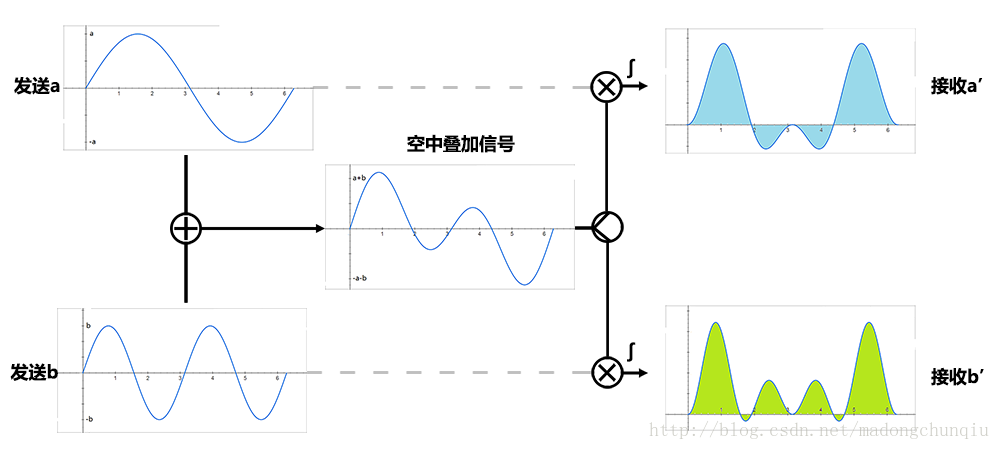

### (b)串并转换

数据传输的典型形式是串行数据流，符号被连续传输，每一个数据符号的频谱可占据整个可利用的带宽。但在并行守护据传输系统中，许多符号被同时传输，减少了那些在串行系统中出现的问题。在 OFDM 系统中，每个传输符号速率的大小大约在几十 bps 到几十 Kbps 之间，所以必须进行串并变换，将输入串行比特流转换为可以传输的 OFDM 符号。由于调制模式可以自适应调节，所以每个子载波的调制模式是可变化的，因而每个子载波可传输的比特数也是可以变化的，所以串并转换需要分配给每个子载波数据段的长度是不一样的。在接收端执行相反的过程，从各个子载波处来的数据被转换回原始的串行数据。

### (c)调制与解调

在本项目中，主要使用DAC（Digital-to-Analog Converter）将数字信号信号转化位模拟信号，具体的，首先用repmat函数对输入信号内插0，将其变成冲激采样串，然后用reshape函数将最接近的采样值填充在两个采样脉冲之间（0阶保持）

ADC，将模拟信号转化为数字信号就是上述的逆过程。使用积分求得给定区间长度的平均值作为该区间的采样值，重新得到离散的采样信号。

### (d)循环前缀CP

由于无线信道的多径效应，从而使符号间产生干扰．为了消除符号问干扰(ISl)，应该在符号间插入保护间隔．插入保护间隔的一般方法是符号间置零，即发送第一个符号后停留一段时间(不发送任何信息)，接下来再发送第二个符号．在OFDM系统中，这样虽然减弱或消除了符号间干扰，由于破坏了子载波间的正交性，从而导致了子载波之间的干扰(ICI)．因此，这种方法在OFDM系统中不能采用．在OFDM系统中，为了既可以消除ISI，又可以消除ICI，通常保护间隔是由循环前缀来充当．当循环前缀的长度大于或等于信道冲击响应长度时，可以有效地消除ISI和ICI．

## 3. Design and Analysis

### 1.System structure

#### (a)Transmitter-----Block1

系统的第一步。接受到信号之后加做行串变化，然后做傅里叶逆变化，频域信号转化为始于时域信号，加入循环前缀。最后输入到模拟信道中。

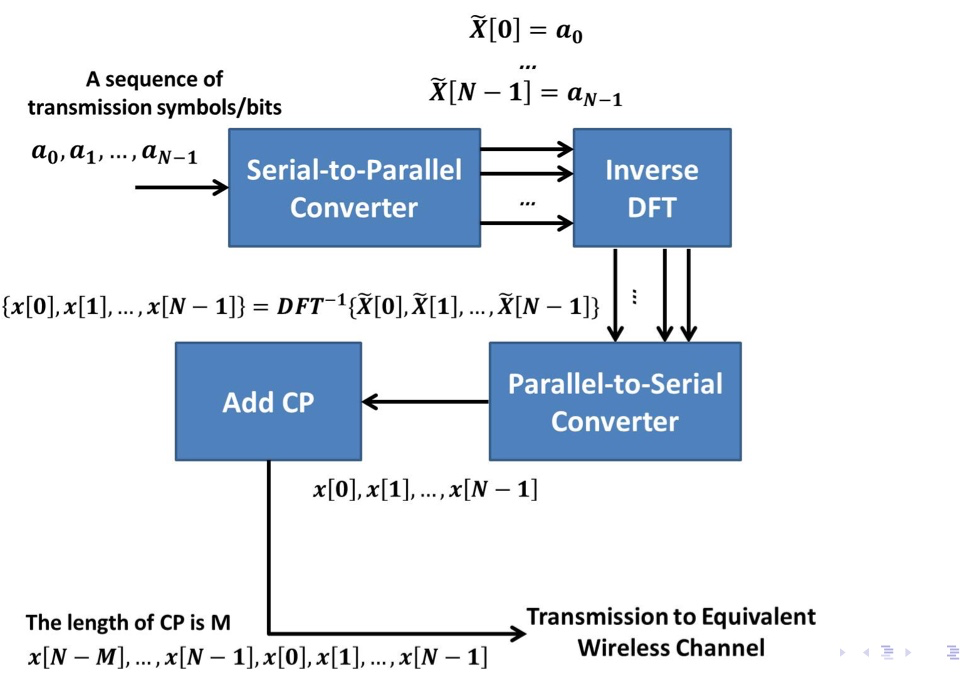

#### (b)Receiver--------Block2

系统的最后一步，与Block1步骤相反。接受到信号之后去除循环前缀，然后做傅里叶变化，时域信号转化为频域信号，最后在频域乘以对应的信道增益得到目标信号。

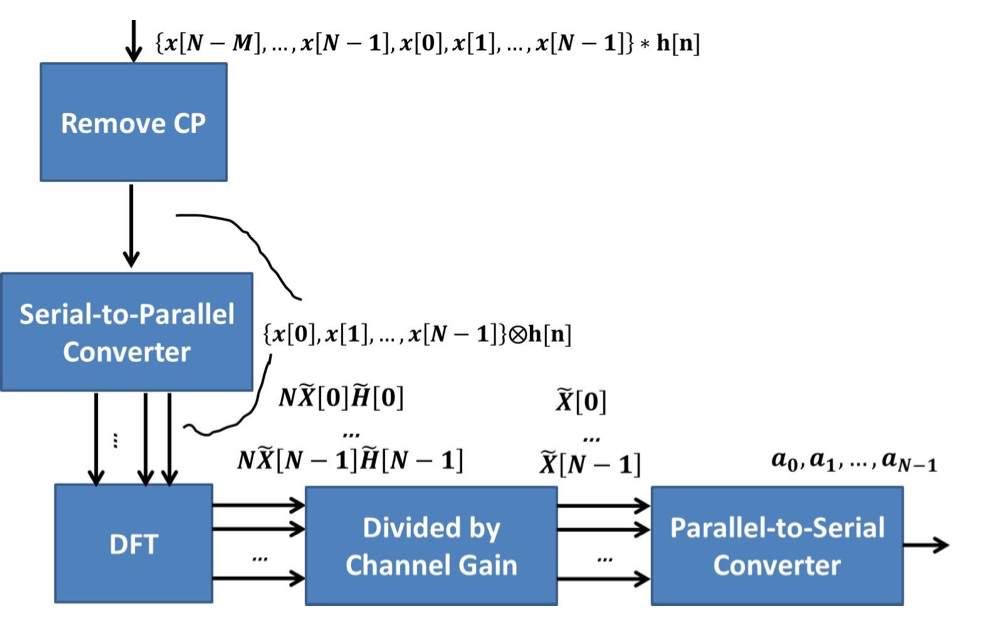

#### (c)DAC+RF-front end------Block3

通过DAC（进行零阶保持），这个过程就是完成了离散信号到连续信号的转变。输出实部和虚部。通过发射器，对信号进行调制并发射。然后对代表原信号实部的信号乘以余弦信号，对代表原信号虚部的信号乘以正弦信号，然后将调制后的两个信号相加成为一个信号并发射。

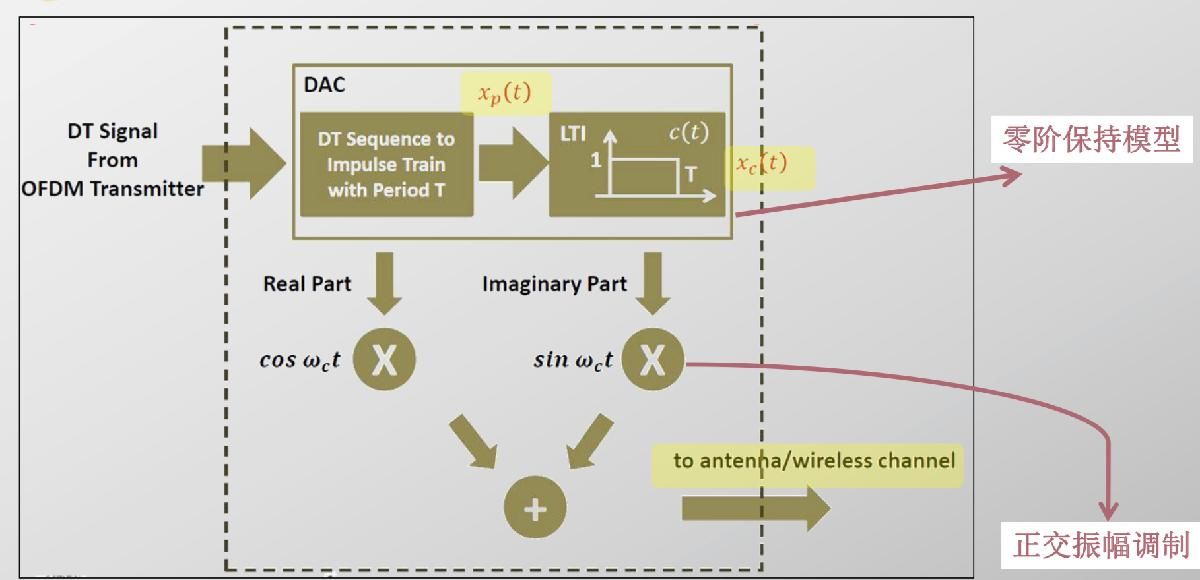

#### (d)Front end +ADC------Block4

1.解调

- 将接收到的信号与载波相乘:$\sin \omega_c t$或$\cos \omega_c t$

- 使用理想低通滤波器得到原信号的实部与虚部。

2.解调之后ADC(Analog-to-Digital Converter)

- 利用积分器对接收功率进行累积，生成DT信号进行后续处理

### 
$$y_{\textrm{int}} =\frac{1}{T}\int_{t-T}^t y_{\textrm{dem}} \left(\tau \right)d\tau$$


### 
$$y_{\textrm{int}} =\frac{1}{T}\int_{t-T}^t y_{\textrm{dem}} \left(\tau \right)d\tau$$


一个采样周期内的平均值作为该时间点的离散值

- $y_{\textrm{int}\;} \left(\textrm{nT}\right)$保留了所有有用的信息

### 2.Code structure

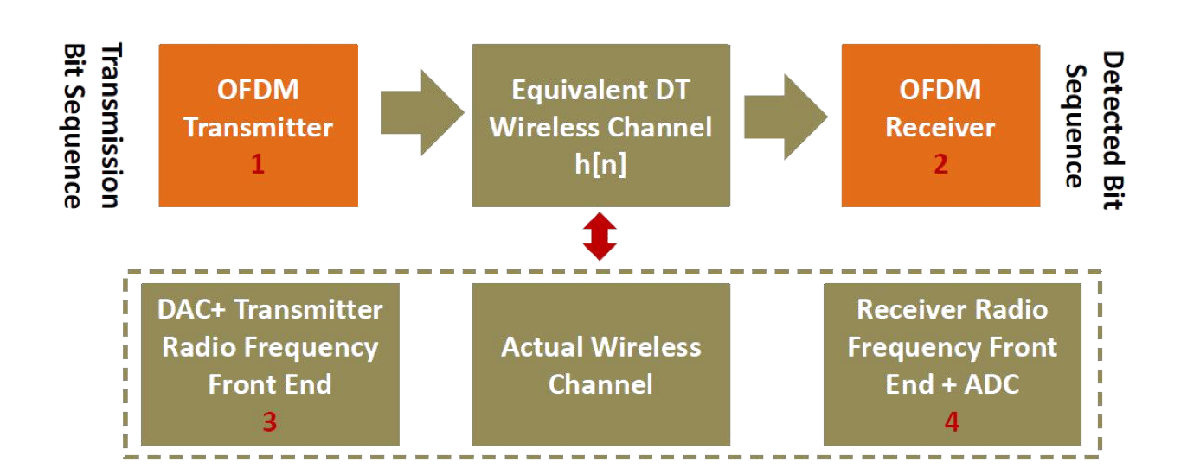

### Our project follow the order showed in above figure:

### 
$$\textrm{Transmitter}\left(\textrm{Block1}\right)\Longrightarrow \textrm{Equivalent}\;\textrm{Wireless}\;\textrm{Channel}\left(\textrm{DAC}+\textrm{Transmitter}\left(\textrm{Block3}\right)\Rightarrow \textrm{Receiver}+\textrm{ADC}\left(\textrm{Block4}\right)\right)\Longrightarrow \textrm{Receiver}\left(\textrm{Block2}\right)$$


## 4. Simulations of OFDM system

### 1.Prepare

随机产生所需的两组原始信号：

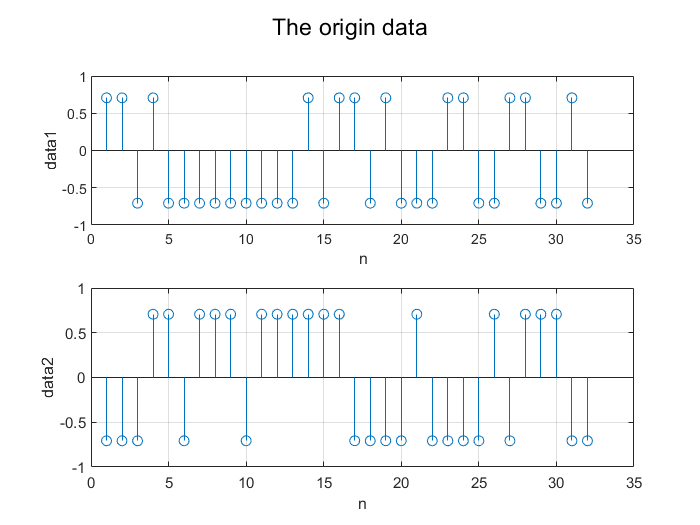

### 2.Block1

应用IDFT(实部和虚部图像)

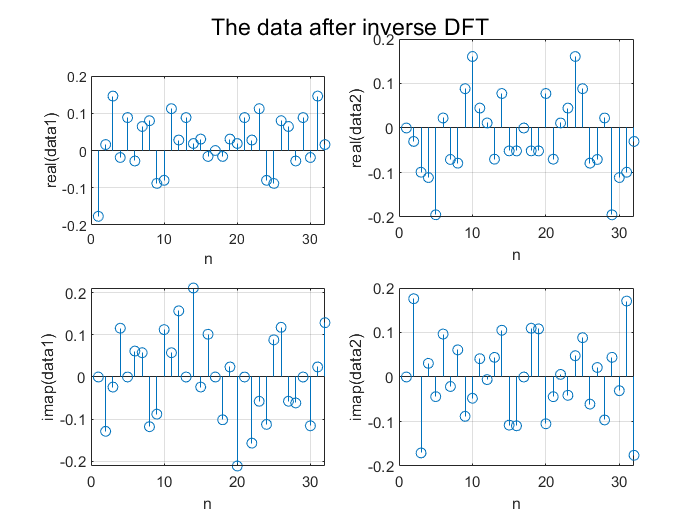

添加cp（由于传输数据为32bit，所以使用的cp最短为32/8=4，在之后进行验证）

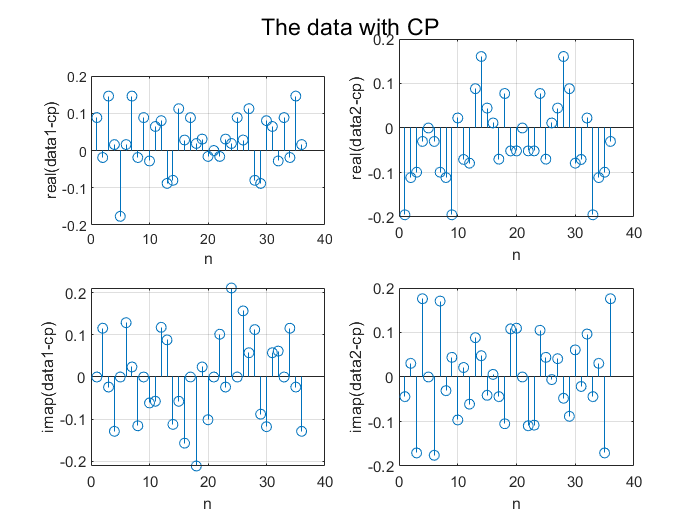

### 3.Block3

将DT信号周期乘以T以获得CT信号，将得到的CT信号与零阶保持模型相乘得到DAC之后的图像。

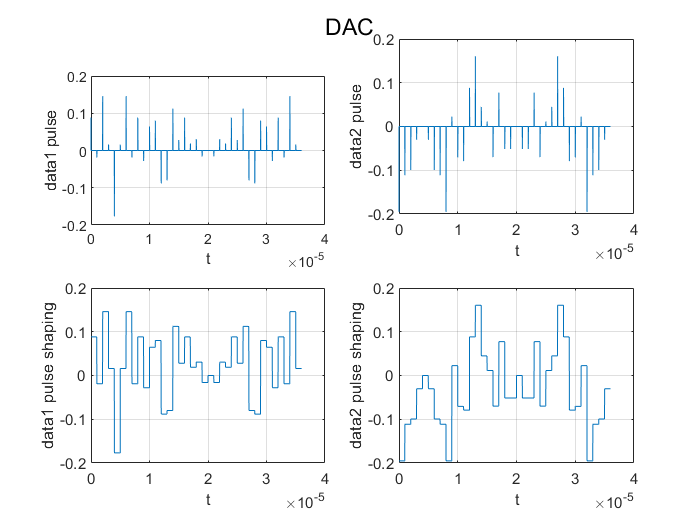

实虚部分离，加载到载波上，进行调制。经过调制后的信号。

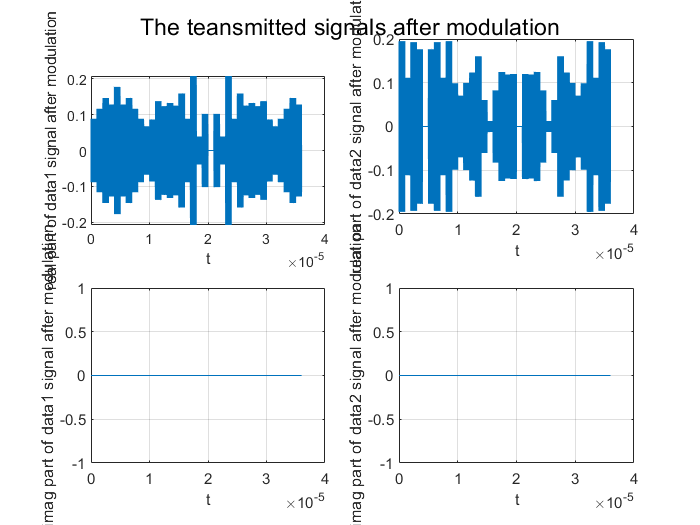

调制后频谱图

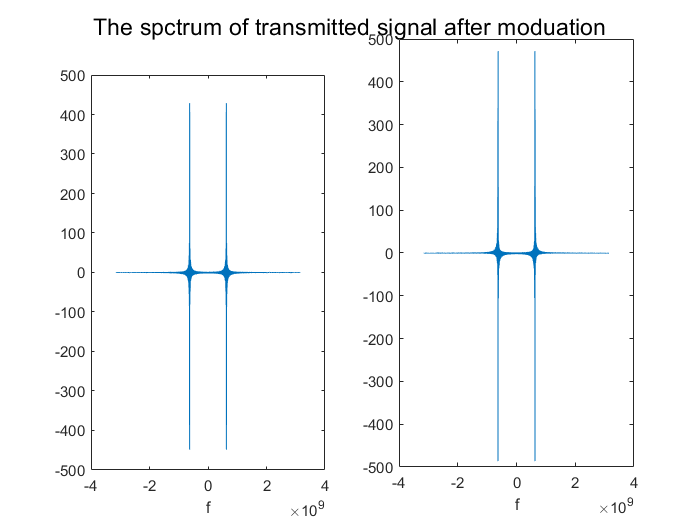

### 4.Block4

信道单位冲击响应：此题中假设为：


$$h\left(t\right)=0\ldotp 5\delta \left(t\right)+0\ldotp 4\delta \left(t-1\ldotp 5T\right)+0\ldotp 35\delta \left(t-2\ldotp 5T\right)+0\ldotp 3\delta \left(t-3T\right)$$


带有信道增益的信号

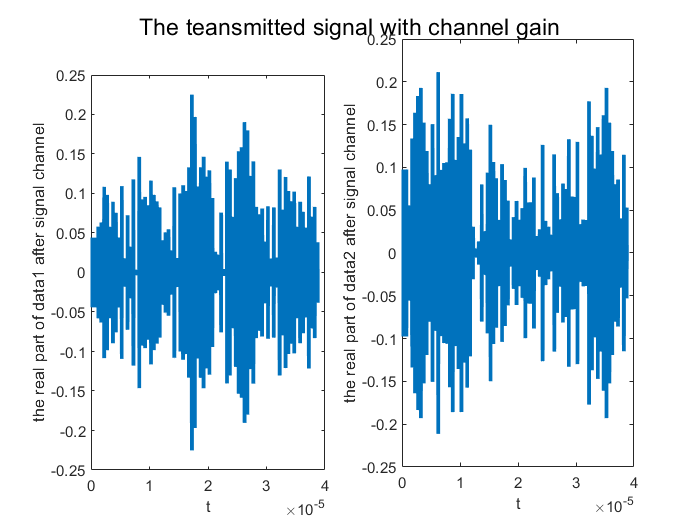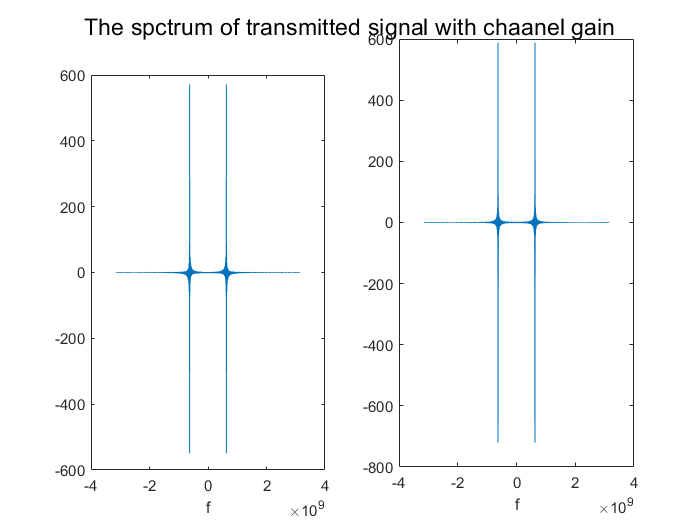

构建理想低通滤波器，用于处理对于原信号进行解调，其截止频率为wc

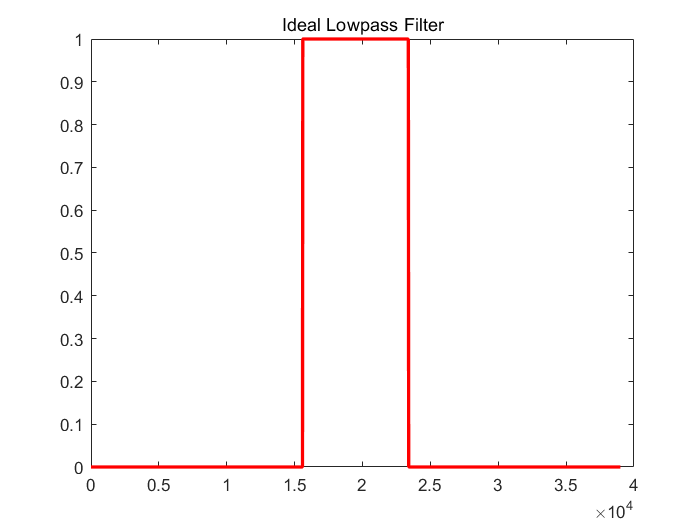

解调信号

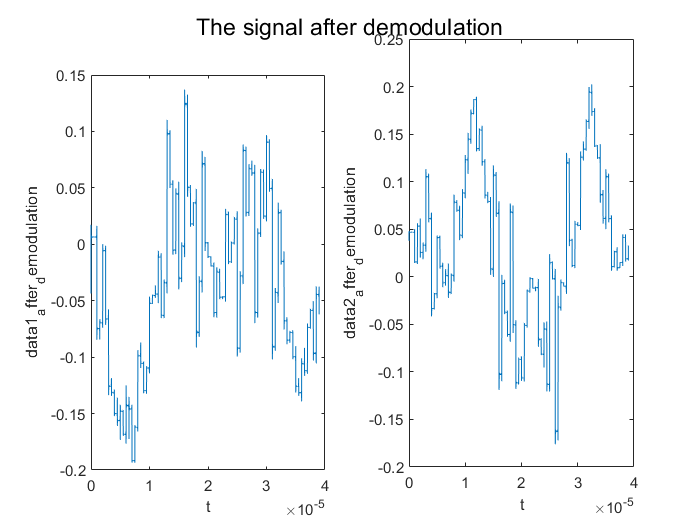

带CP的信后经过ADC

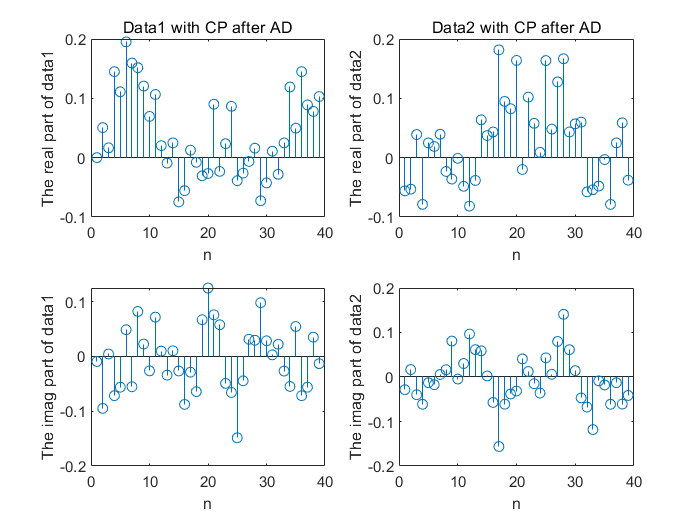

### 5.Block2

去除

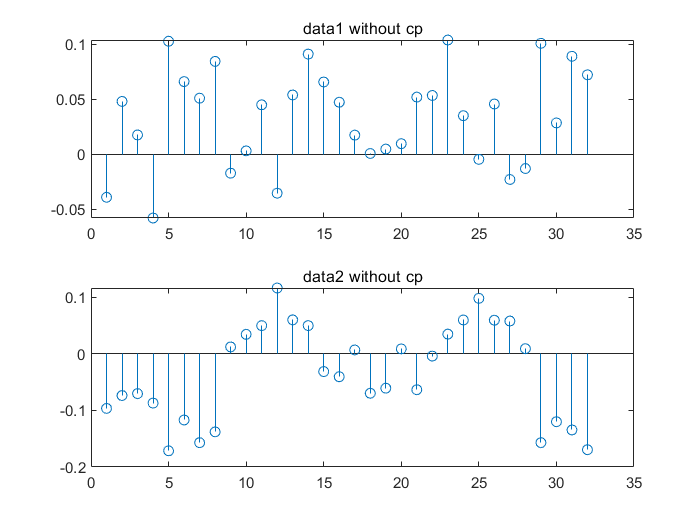

DFT

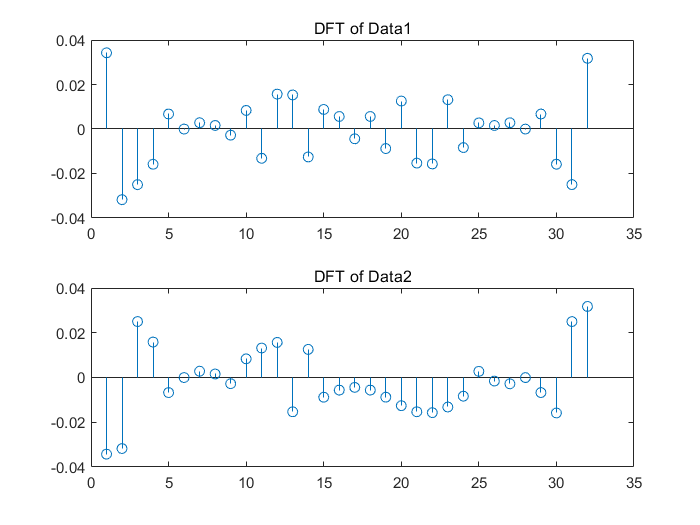

恢复后的信号

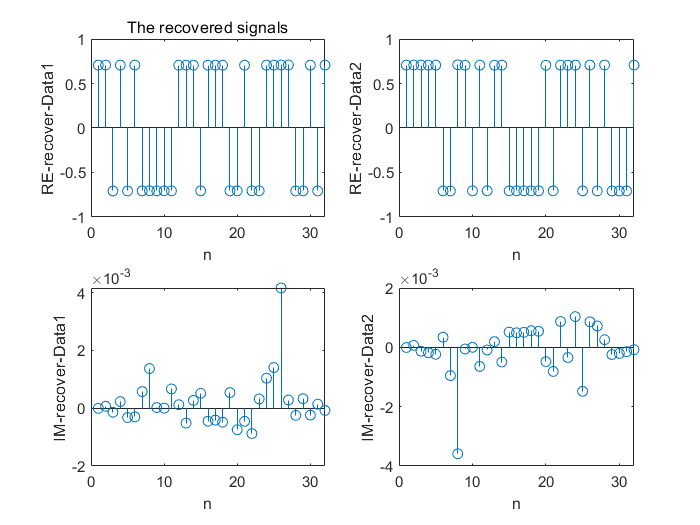

### 6.Channel Estimation

接收器得到信号与原始信号对比，误差均在5%以下

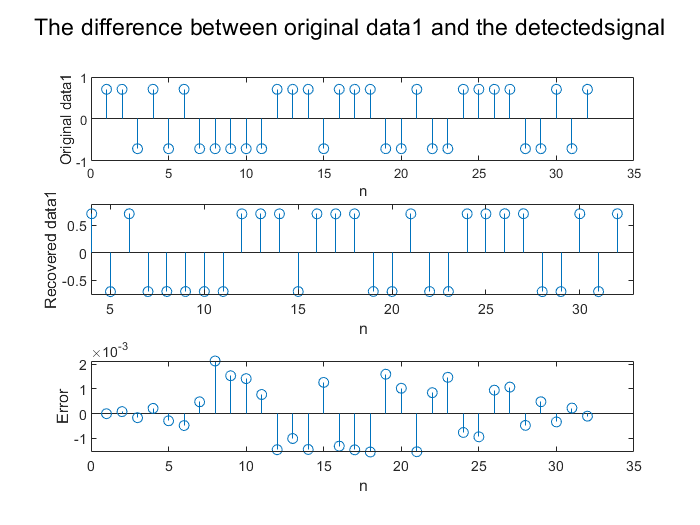

## `maxerror1 = 0.1279`

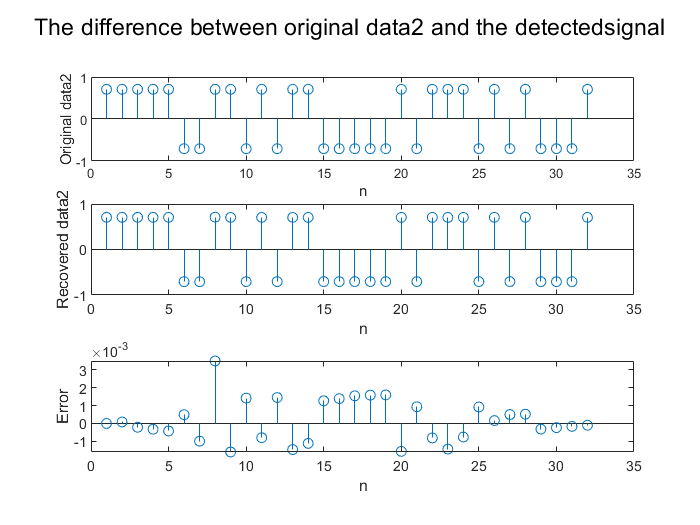

## `maxerror2 = 0.1313`

### `7.Derive H[n],h[n]`

由ak求解Hk,构建一个已知的计算函数tone经过以上处理步骤用于计算H

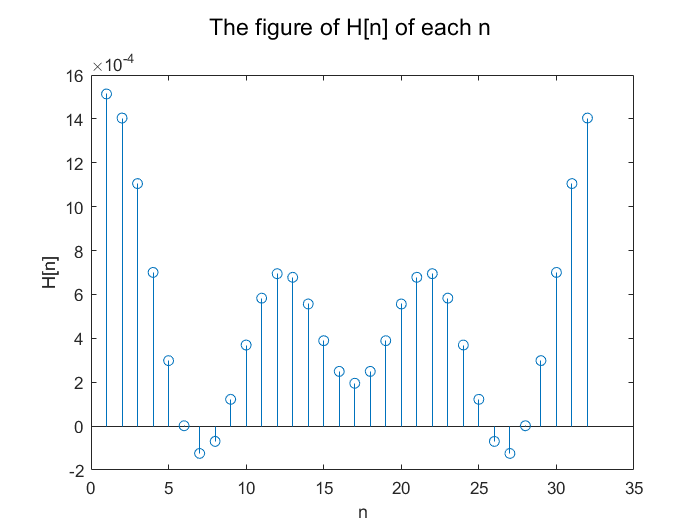

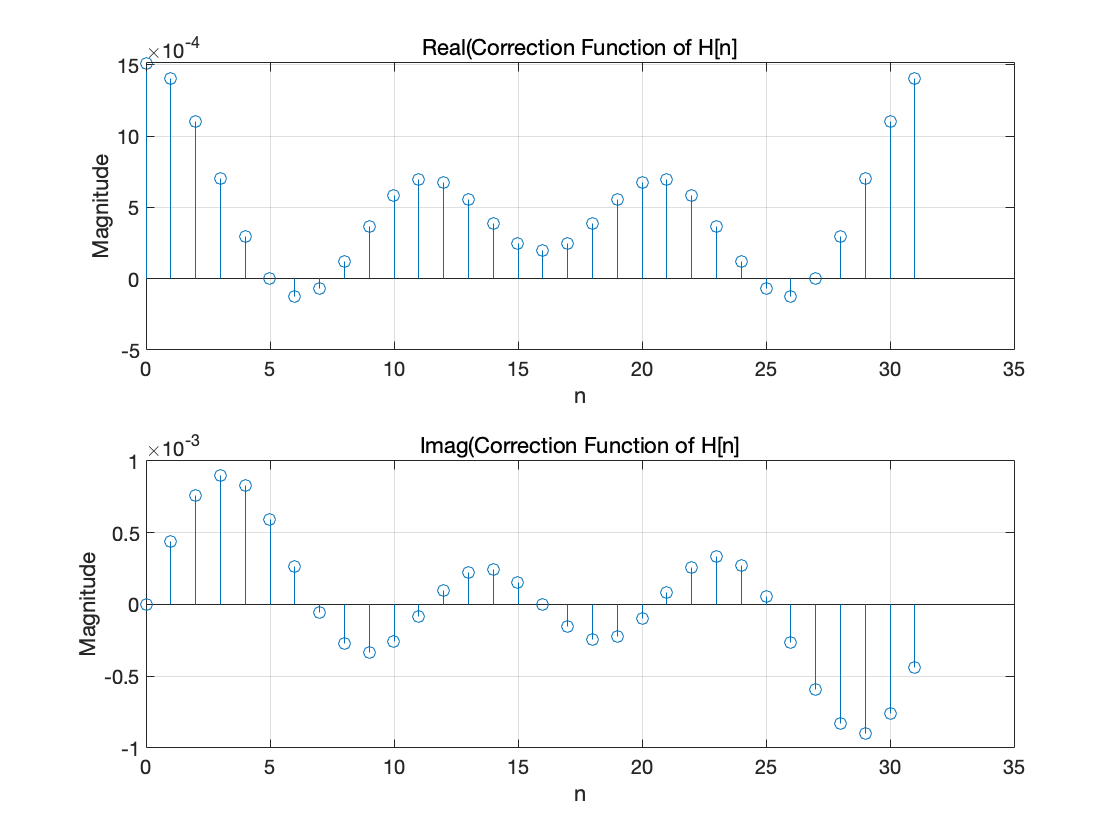

经过ifft后可以得到h[n] = ifft(H[n])，可以与h[t]进行比较

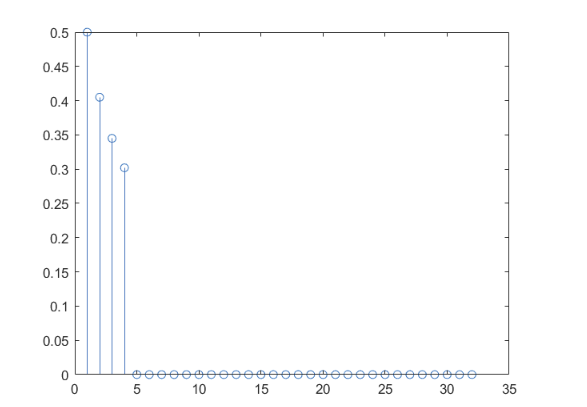

## 5.Conclusion

### 1.CP长度估计

CP长度的优化选择是直接影响OFDM系统性能的因素之一。

- 如果CP长度过小，则不能消除码间干扰，其长度下限应大于等于信号最大延迟扩展。当CP长度大于最大延迟扩展时，CP长度越小越好。

- 若CP长度过大，则会降低低功率损耗和数据传输速率。因此当CP长度等于最大延迟扩展时，OFDM性能最好，系统对多径干扰的抵抗能力最强。

由上述情况分析，我们可以得到误差小于5%，总结可以的出：$h\left\lbrack n\right\rbrack \not= 0,n=0,1,2,3$ 因此$h\left\lbrack n\right\rbrack$的非零长度为4.

又因为CP的长度应该大于等于L-1，所以在这种情况下，CP长度应该$\ge 3$。但当我们结合效率分析，为了提高效率，CP需要尽可能小，所以我们选择CP长度为3。

### 2.$h\left\lbrack t\right\rbrack$与$h\left\lbrack n\right\rbrack$的关系

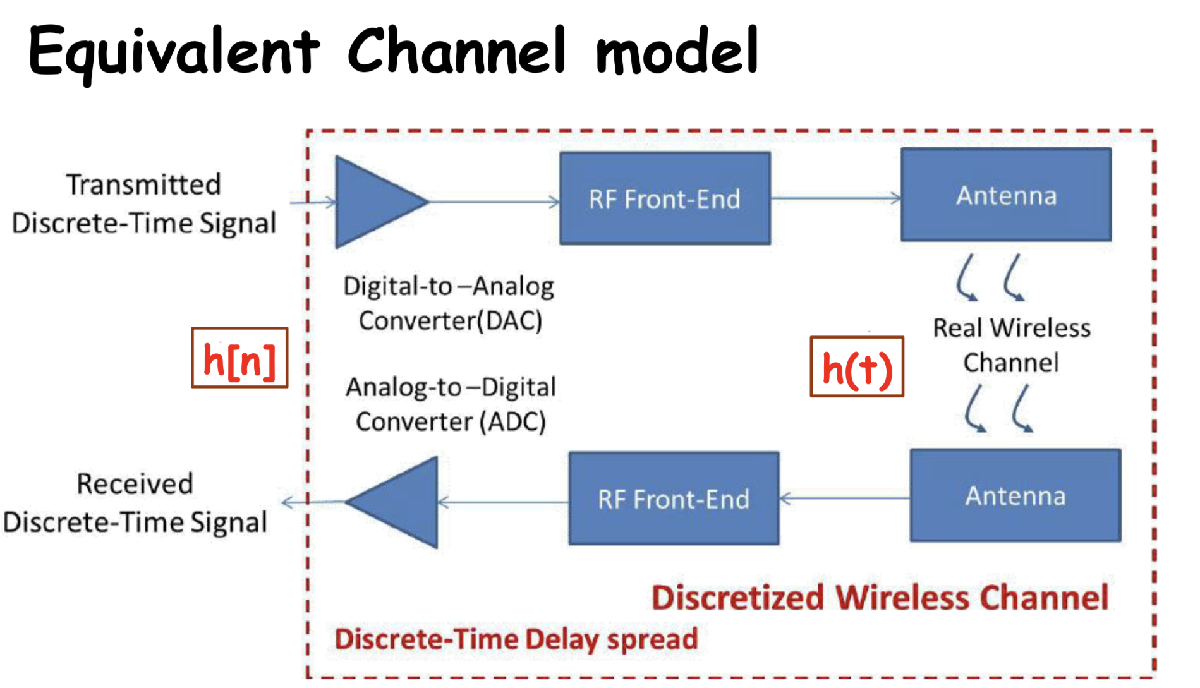

我们可以得到模拟信道中的$h\left(t\right)$图像

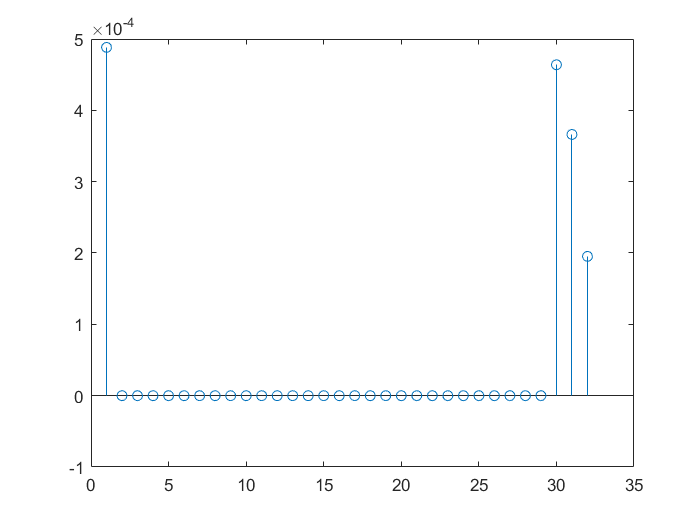

我们从系统中可以得到$h\left\lbrack n\right\rbrack$图像为

从图像上可以得出结论：$h\left\lbrack t\right\rbrack$就是$h\left\lbrack n\right\rbrack$缩小了T倍。

## 6. Discussions

### 1.OFDM

OFDM（Orthogonal Frequency Division Multiplexing）是一种特殊的多载波传输方式，由于各子载波之间存在正交性，允许子信道的频谱互相重叠，与常规的频分复用系统相比，OFDM 可以最大限度的利用频谱资源。同时他把高速数据通过串并转换，使得每个子载波上的数据符号持续长度相对增加，降低了子信道的信息速率，将频率选择性衰落信道转换为平坦衰落信道，从而具有良好的抗噪声、抗多径干扰的能力，适于在频率选择性衰落信道中进行高速数据的传输。在 OFDM中引入循环前缀cp，克服了 OFDM 相邻块之间的干扰，保持了载波间的正交性，同时循环前缀长度大于信道扩展长度，有效地抑制了码间干扰（ISI），可以看出，OFDM 技术抗多径能力强、频谱利用率高、易于实现的优势对短波数据通信具有广阔的应用价值，为提高短波通信频谱利用率和传输速率提供了新的解决方案。

#### OFDM 主要有下列一些优点： 

(1)OFDM 在对抗干扰及衰落的优势：把高速数据流通过串并变换，使得每个 子载波上的数据符号持续长度相对增加，可有效对抗信号波形间的干扰 ISI，适用 于多径信道存在频率选择性，而所有子载波都处于深衰落的概率极小，OFDM 系 统可通过动态比特分配和动态子信道分配的方法，充分利用信噪比较高的子信道， 提高系统性能。因为窄带干扰只能影响一小部分的子载波，因此 OFDM 可以在某 种程度上抵抗这种窄带干扰。OFDM 的以上优势减小了接收机的复杂度，甚至可 以不用均衡器，仅采用插入循环前缀的方法消除 ISI 的不利影响，大大节省了系统 花费减小了系统复杂度和功率消耗。 

(2)OFDM 系统由于子载波之间存在正交性，允许子信道的频谱相互重叠，因 此与常规的频分复用相比，OFDM 可以最大限度地利用频谱资源。这一点在频谱 资源有限的无线环境中尤为重要，当子载波数目很大时，系统的频谱利用率趋于 2Baud/Hz。 

(3)各子信道的正交调制和解调可通过离散傅利叶反变换(IDFT)和离散傅利叶 变换(DFT)实现。对 N 很大(N>32)的系统，可以通过快速傅立叶变换(FFT)来实现。 基于 FFT 的系统在计算方面更有效，并且随着大规模集成电路技术和 DSP 的发展， IFFT 和 EFT 都非常容易实现。 

(4)OFDM 的开放灵活性：无论从无线数据业务的使用需求，还是从移动通信系统自身要求，都希望物理层支持非对称高速数据传输,而 OFDM 系统可以很容易使用不同数量的子载波来实现上下链路中不同的传输速率。OFDM 较易与其它多种接入方式结合，构成跳频 OFDM 及 OFDM-TDMA 等。

#### OFDM 技术的不足： 

(1)由于 OFDM 系统内存在多个正交子载波，而且其输出信号是多个子信道的 叠加，因此对子信道的正交性有严格要求。而由于无线信道的时变性，还有发射机载波和本地振荡器的频率偏差，所以 OFDM 易受频率偏差的影响。 

(2)如果多个子信号的相位一致时，所得到的叠加信号的瞬时功率会远大于信号的功率，出现较大的峰值与均值功率比(PAR)，这个比值的增大会降低射频放大器的功率效率，使系统性能恶化.

### 2.无线通信技术

到目前为止，无线通信大约经历了四个阶段。 

(1)1G 阶段 

主要采用的是模拟技术和频分多址(FDMA)技术。由于受到传输带宽的限制，不能进行移动通信的长途温游，只能是一种区域性的移动通信系统。

(2)2G 阶段 

主要采用的是数字的时分多址(TDMA)技术和码分多址(CDMA)技术。全球主要有 GSM 和 CDMA 两种体制。由于第二代采用不同的制式，移动通信标准不统一，用户只能在同一制式覆盖的范围内进行漫游，因而无法进行全球漫游，由于第二代数字移动通信系统带宽有限，限制了数据业务的应用，也无法实现高速率的业务如移动的多媒体业务。 

(3)3G 阶段 

与从前以模拟技术为代表的第一代和目前正在使用的第二代移动通信技术相比，3G 将有更宽的带宽，其传输速度最低为 384K，最高为 2M，带宽可达 5MHz以上。第三代移动通信网络能将高速移动接入和基于互联网协议的服务结合起来，提高无线频率利用效率。提供包括卫星在内的全球覆盖第 3 页并实现有线和无线以及不同无线网络之间业务的无缝连接。 

(4)4G 阶段 

由于第三代移动通信系统仍是基于地面标准不一的区域性通信系统，尽管其传输速率可高达 2 Mb/s，但仍无法满足多媒体通信的要求，因此，第四代移动通信系统(4G)的研究随之应运而生。第四代移动通信技术的概念可称为广带 (Broadband)接入和分布网络，具有非对称超过 2 Mb/s的数据传输能力，对全速移动用户能提供 150 Mb/s的高质量影像服务，将首次实现三维图像的高质量传输。他包括广带无线固定接入、广带无线局域网、移动广带系统和互操作的广播网络(基 于地面和卫星系统)。

无线信道包括了电波的多径衰落，时延扩展，以及多普勒效应，在移动通信中，必须要充分考虑这些特性，并提出相关的解决方案。 

(1)时延扩展 

无线信道中电波的传播不是单一路径，而是许多路径来的众多反射波的合成。由于电波通过各个路径的距离不同，因而各个路径来的反射波到达时间不同，也就是各信号的时延不同。当发送端发送一个极窄的脉冲信号时，移动台接收的信号由许多不同时延的脉冲组成，这被称之为时延扩展。 

(2)多径衰落 

由于各个路径来的反射波到达时间不同，相位也就不同。不同相位的多个信号在接收端迭加，有时迭加而加强（方向相同），有时迭加而减弱（方向相反）。这样，接收信号的幅度将急剧变化，即产生了快衰落。此外，接收信号除瞬时值出现快衰落之外，场强中值（平均值）也会出现缓慢变化。主要是由地区位置的改变以及气象条件变化造成的，以致电波的折射传播随时间变化而变化，多径传播到达固定接收点的信号的时延随之变化。这种由阴影效应和气象原因引起的信号变化，称为慢衰落。这种衰落是由多种路径引起的，所以称为多径衰落。 

(3)多普勒效应 

由于移动通信中移动台的移动性，如前所述，无线信道中还会有多普勒效应。在移动通 

信中，当移动台移向基站时，频率变高，远离基站时，频率变低。这就是有多普勒效应效应引起的。

## 7.Code

- Complete the Simulation of Block1,2,3

- Design the receiver's RF front-end + ADC(Block 4), explain why your design can lead to correct signal detection.

- Derive h[n] and discuss the relation between h(t) and h[n],determine the length of CP

- Channel Estimation(Transmit two random discrete time signals by OFDM)

发射一个已知信号，在接收端对接收的信号进行分析以求出信道增益。首先产生一个指定的信号，通过模拟信道得到接收信号，在频域中，用接收信号除以发射信号，即可得到。

### Prepare 

clc,clear,close all;

参数设置：

fc = 100*10^6;
wc = 2*pi*fc;
fct = 10^9;
Fct = 1/fct;
T = 10^(-6);
fs = 1/T;
N = 32;

随机产生所需的两组信号：

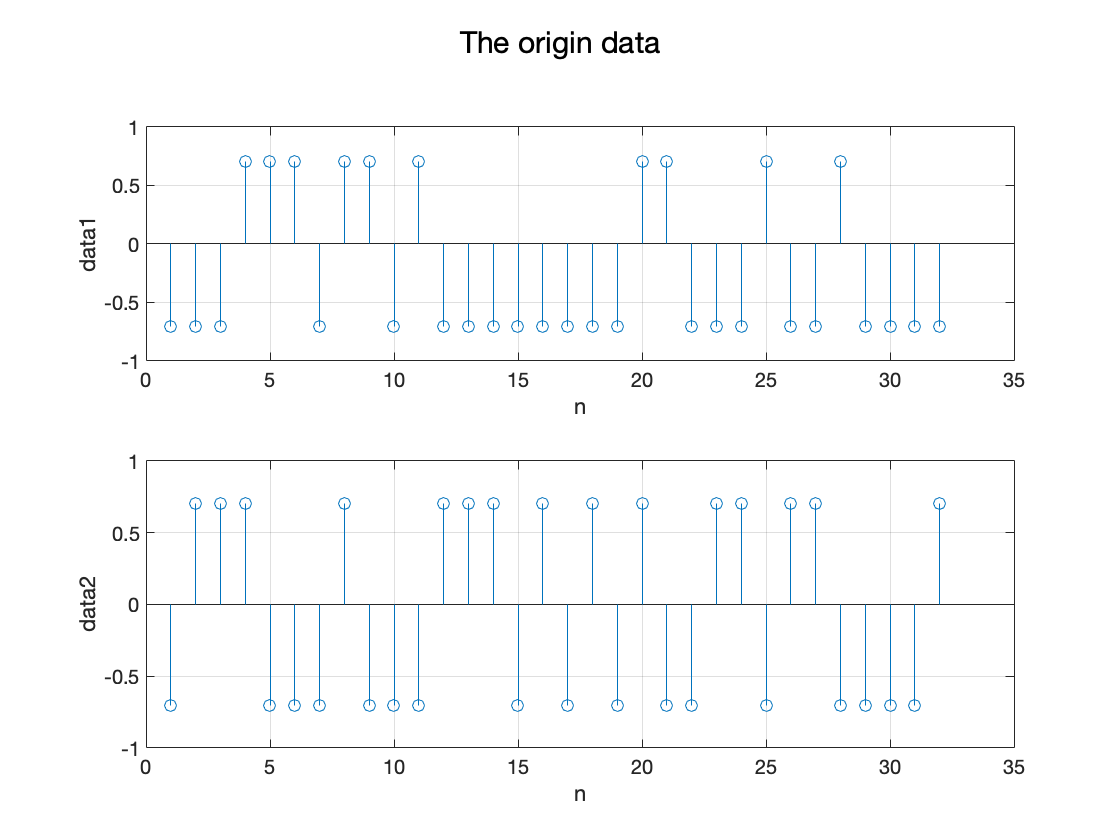

data1_ori = 0.707*(2*round(rand([1,N]))-1);
data2_ori =  0.707*(2*round(rand([1,N]))-1);

data1 = data1_ori;
data2 = data2_ori;
%-------------------------------------------
figure
subplot(2,1,1);
stem(1:N,data1_ori),xlabel('n'),ylabel('data1');grid on
suptitle('The origin data');
subplot(2,1,2);
stem(1:N,data2_ori),xlabel('n'),ylabel('data2');grid on

### Design of block1:

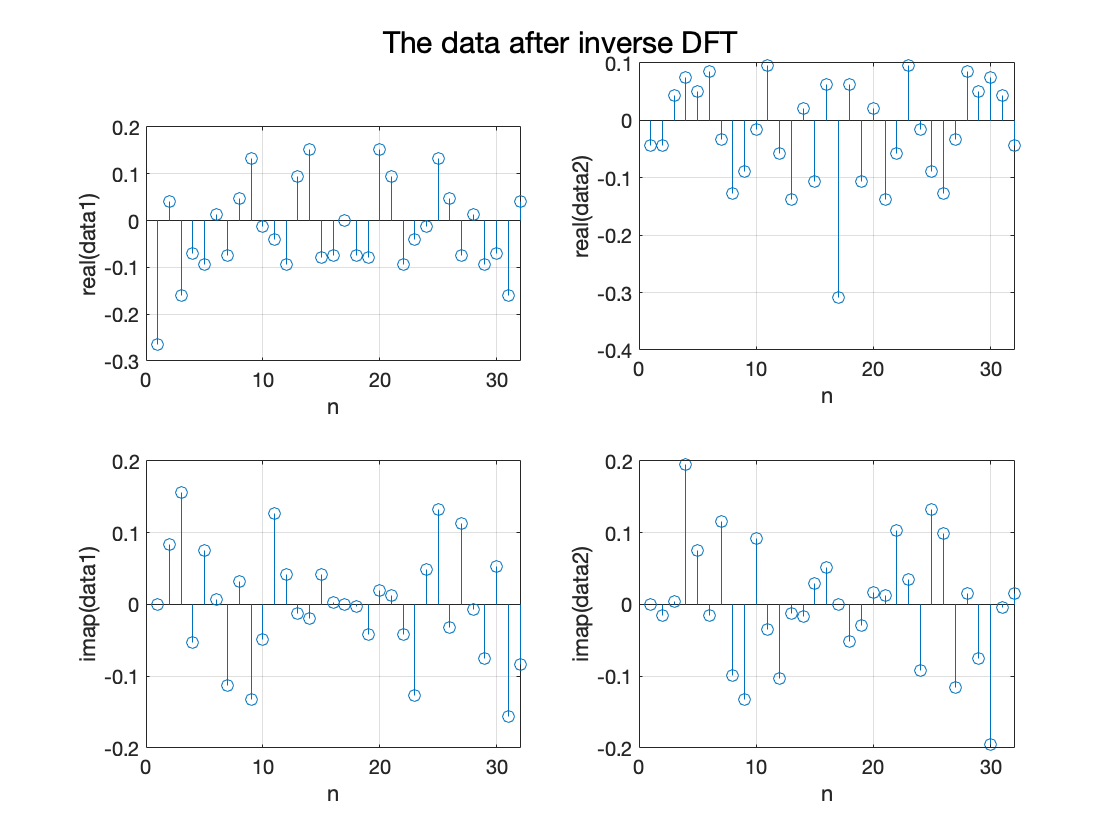

pData1 = data1_ori';
pDdta2 = data2_ori';%串并转换

Data1 = ifft(pData1);
Data2 = ifft(pDdta2);%应用ifft
%--------------------------------------
figure
subplot(2,2,1);
stem(1:N,real(Data1)),xlabel('n'),ylabel('real(data1)');grid on
suptitle('The data after inverse DFT');
subplot(2,2,3);
stem(1:N,imag(Data1)),xlabel('n'),ylabel('imap(data1)');grid on

subplot(2,2,2);
stem(1:N,real(Data2)),xlabel('n'),ylabel('real(data2)');grid on
subplot(2,2,4);
stem(1:N,imag(Data2)),xlabel('n'),ylabel('imap(data2)');grid on

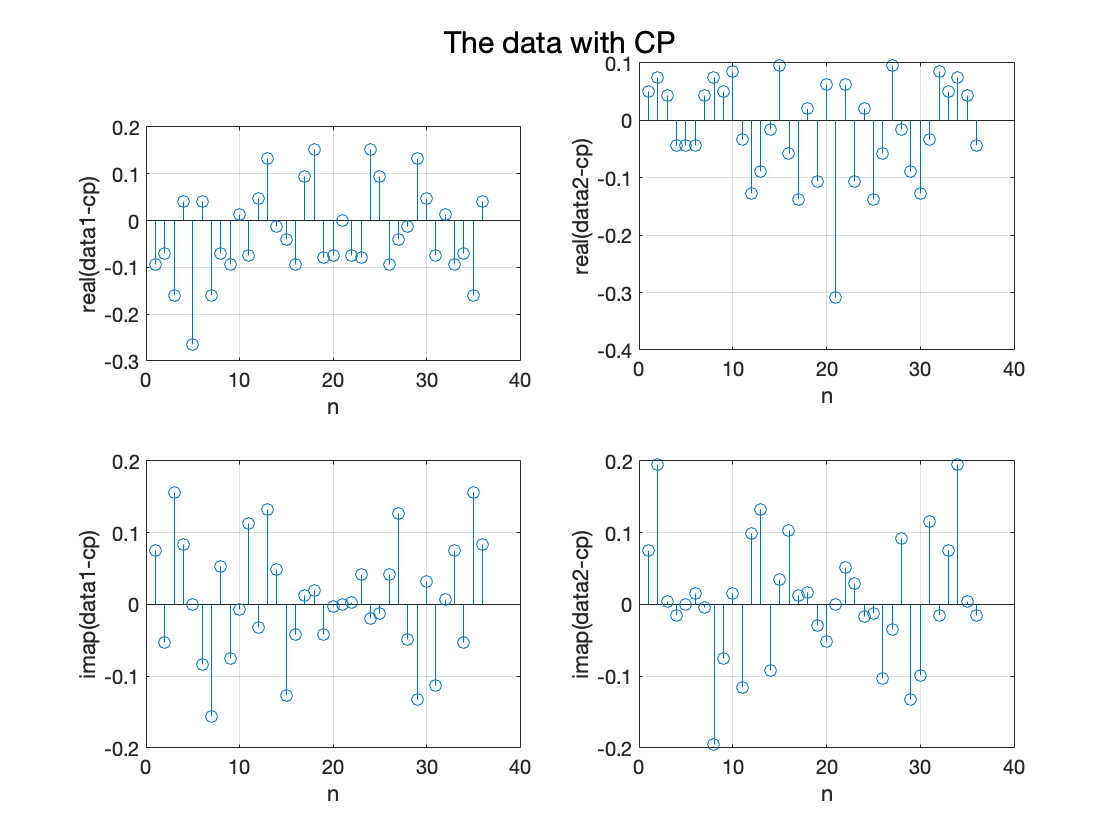


%--------------------------------------
data1 = Data1';
data2 = Data2';%并串转换

%添加cp
%由于传输数据为32bit，所以使用的cp最短为32/8=4，可在之后进行验证
data1_cp = [data1(end-3:end),data1];
data2_cp = [data2(end-3:end),data2];

%--------------------------------------
figure
subplot(2,2,1);
stem(1:N+4,real(data1_cp)),xlabel('n'),ylabel('real(data1-cp)');grid on
suptitle('The data with CP');
subplot(2,2,3);
stem(1:N+4,imag(data1_cp)),xlabel('n'),ylabel('imap(data1-cp)');grid on

subplot(2,2,2);
stem(1:N+4,real(data2_cp)),xlabel('n'),ylabel('real(data2-cp)');grid on
subplot(2,2,4);
stem(1:N+4,imag(data2_cp)),xlabel('n'),ylabel('imap(data2-cp)');grid on

### Block 3:

DAC + Tramsmitter Radio Frequency Front End

%将DT信号周期乘以T以获得CT信号
ut=T/1000:T/1000:(N+4)*T;
data1_p = upsample(data1_cp,1000);
data2_p = upsample(data2_cp,1000);
% data1_p = data1_periodT(1:end-999)

%将上面得到的CT信号与零阶保持模型相乘，这里使用repmat与reshape进行模拟
data1_cc = repmat(data1_cp,1000,1);
data1_c = reshape(data1_cc,1,[]);
data2_cc = repmat(data2_cp,1000,1);
data2_c = reshape(data2_cc,1,[]);

%----------------------------------------------
figure
subplot(2,2,1);
plot(ut,data1_p),xlabel('t'),ylabel('data1 pulse');grid on;

suptitle('DAC');
subplot(2,2,3);
plot(ut,data1_c),xlabel('t'),ylabel("data1 pulse shaping");grid on;


subplot(2,2,2);
plot(ut,data2_p),xlabel('t'),ylabel('data2 pulse');grid on;

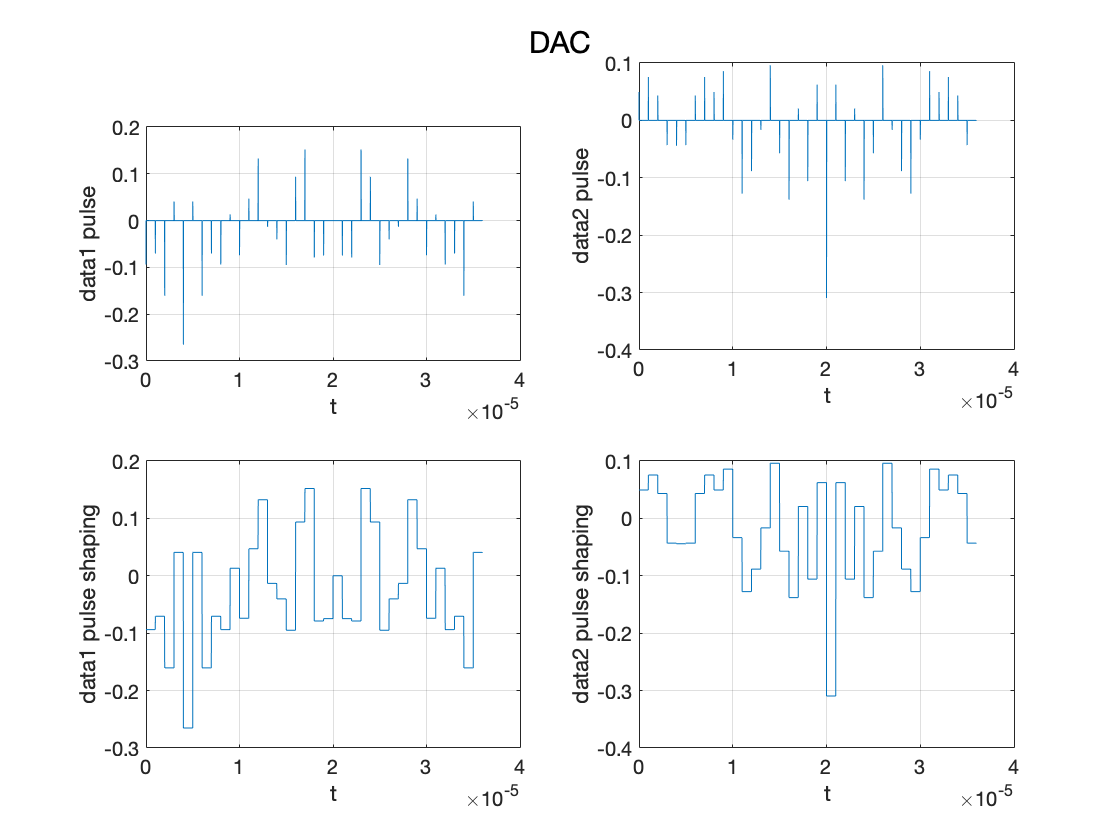

subplot(2,2,4);
plot(ut,data2_c),xlabel('t'),ylabel("data2 pulse shaping");grid on;

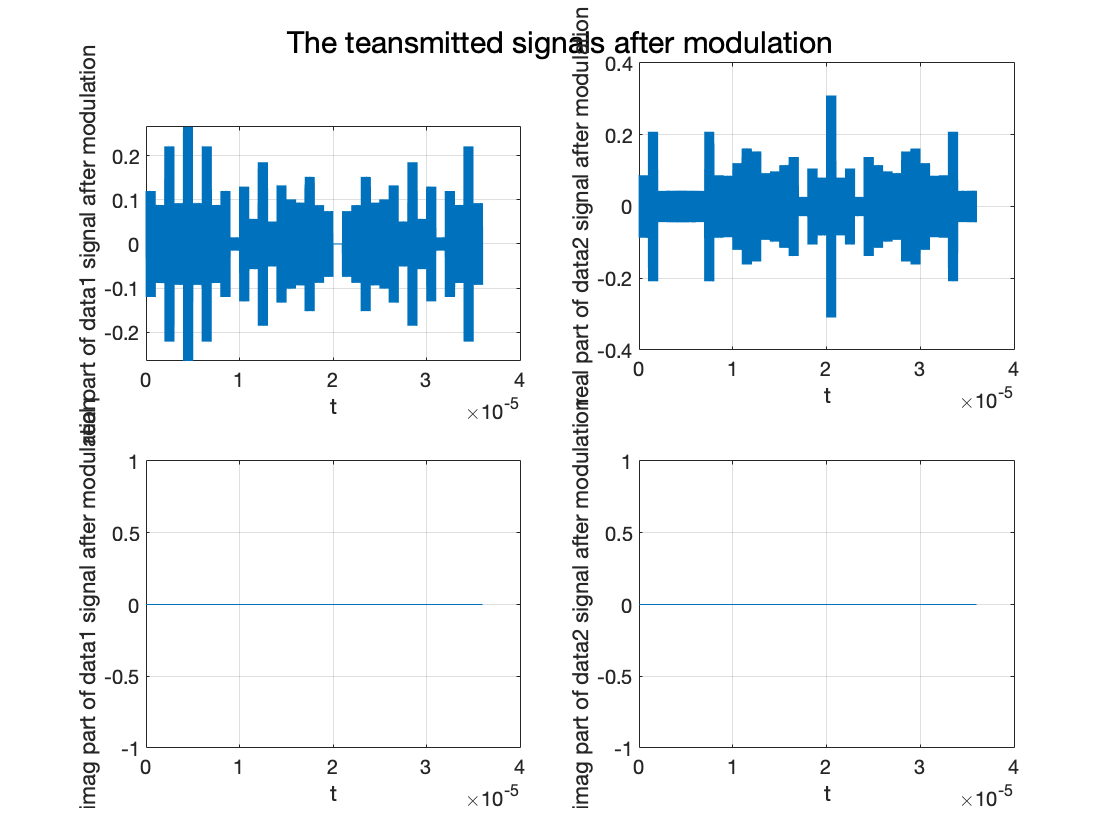

%------------------------------------------------

%实虚部分离，加载到载波上，进行调制
real_data1 = real(data1_c);
imag_data1 = imag(data1_c);
real_data2 = real(data2_c);
imag_data2 = imag(data2_c);
t = ut;
cos_sig = cos(wc*t);
sin_sig = sin(wc*t);
data1_tx = real_data1.*cos_sig+imag_data1.*sin_sig;
data2_tx = real_data2.*cos_sig+imag_data2.*sin_sig;

%-------------------------------------------------
figure
subplot(2,2,1);
plot(ut,real(data1_tx)),xlabel( 't'),ylabel('real part of data1 signal after modulation');grid on
suptitle('The teansmitted signals after modulation');
subplot(2,2,3);
plot(ut,imag(data1_tx)),xlabel( 't'),ylabel('imag part of data1 signal after modulation');grid on
subplot(2,2,2);
plot(ut,real(data2_tx)),xlabel( 't'),ylabel('real part of data2 signal after modulation');grid on
subplot(2,2,4);
 plot(ut,imag(data2_tx)),xlabel( 't'),ylabel('imag part of data2 signal after modulation');grid on

%-------------------------------------------------

uf = (-pi: 2*pi/length(data1_tx):pi-2*pi/length(data1_tx))/(Fct);
figure
%lc = fft(cos_sig);
subplot(1,2,1);
plot(uf,fftshift(fft(data1_tx)));xlabel('f')

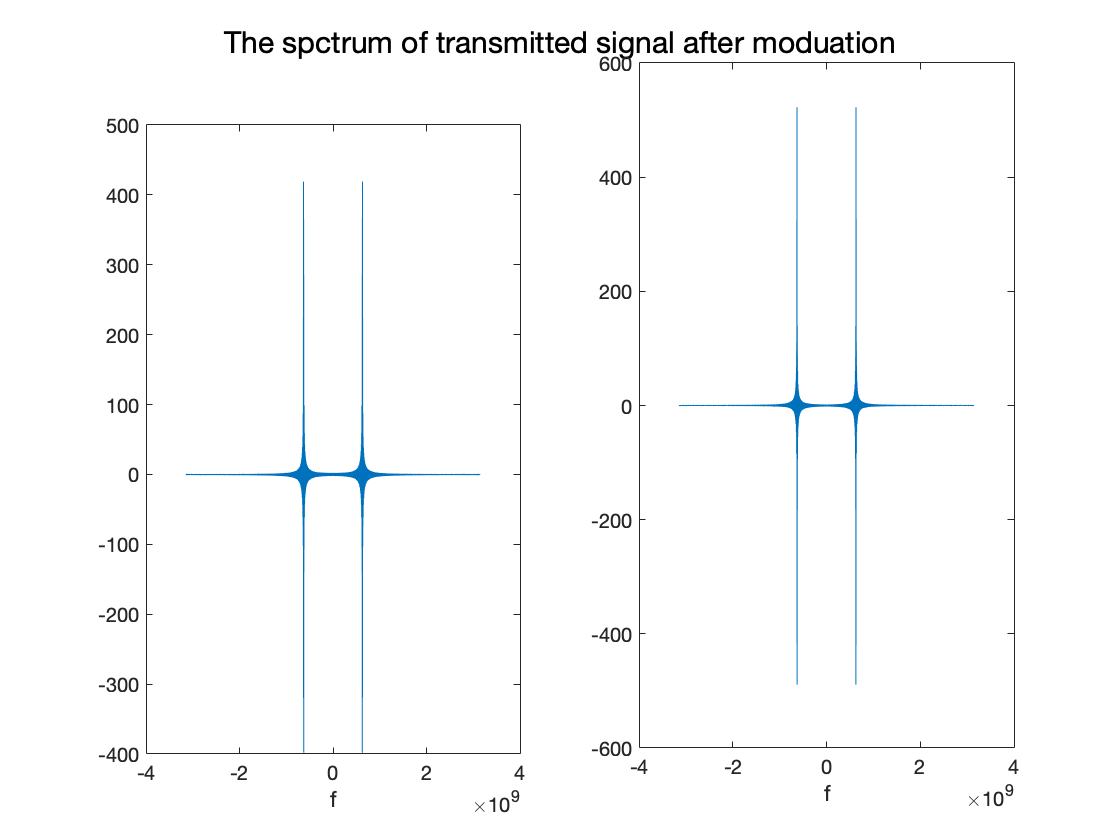

suptitle('The spctrum of transmitted signal after moduation');
subplot(1,2,2);
plot(uf,fftshift(fft(data2_tx)));xlabel('f');

### Block 4:

Receiver Radio Frequency Front End + ADC

信道单位冲击响应：此题中假设为：


$$h\left(t\right)=0\ldotp 5\delta \left(t\right)+0\ldotp 4\delta \left(t-1\ldotp 5T\right)+0\ldotp 35\delta \left(t-2\ldotp 5T\right)+0\ldotp 3\delta \left(t-3T\right)$$


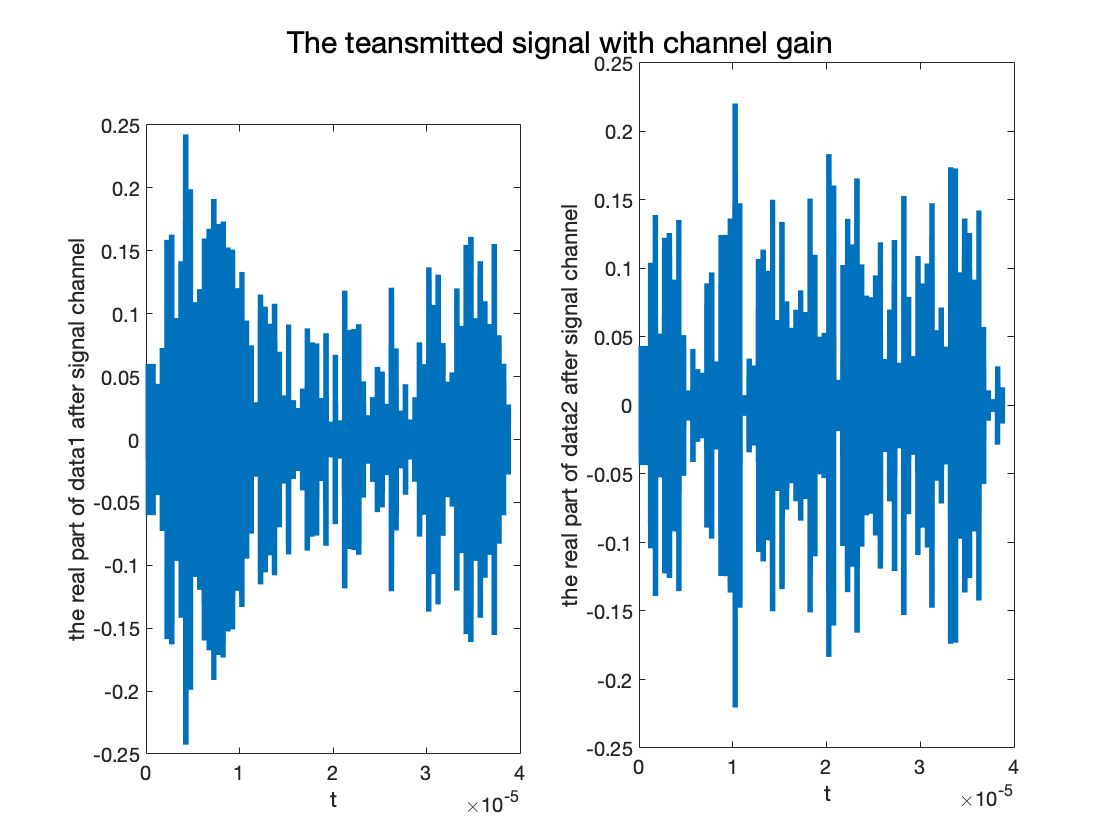

ht = [0.5 zeros(1,1499) 0.4 zeros(1,999) 0.35 zeros(1,499) 0.3];
data1_with_h = conv(data1_tx,ht);
data2_with_h = conv(data2_tx,ht);
uut = T/1000:T/1000:(N+7)*T;
figure
subplot(1,2,1);
plot(uut,real(data1_with_h));xlabel('t');ylabel('the real part of data1 after signal channel');
suptitle('The teansmitted signal with channel gain');
subplot(1,2,2);
plot(uut,real(data2_with_h));xlabel('t');ylabel('the real part of data2 after signal channel');

% plot(uut,imag(data1_with_h));
uuf = (-pi : 2*pi/length(data1_with_h):pi-2*pi/length(data1_with_h))/(Fct);
figure
subplot(1,2,1);
plot(uuf,fftshift(fft(data1_with_h)));xlabel('f');

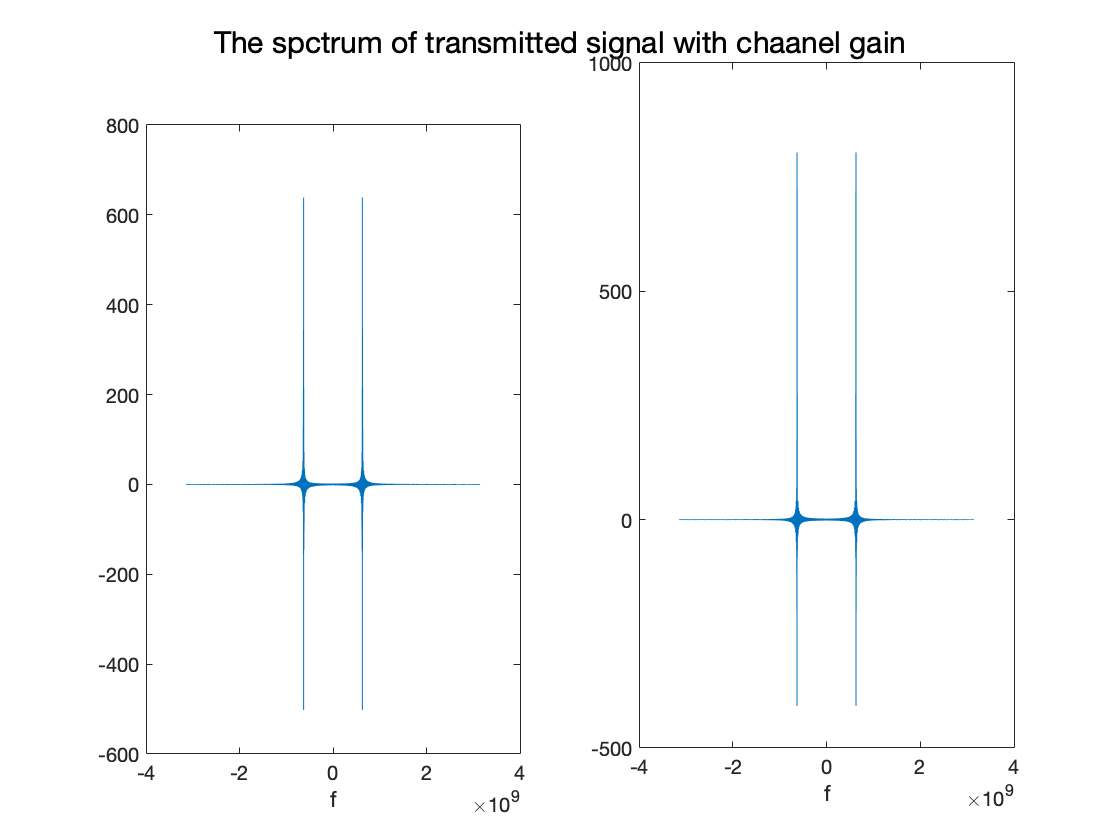

suptitle('The spctrum of transmitted signal with chaanel gain');
subplot(1,2,2);
plot(uuf,fftshift(fft(data2_with_h)));xlabel('f');

构建理想低通滤波器，用于处理对于原信号进行解调，其截止频率为wc

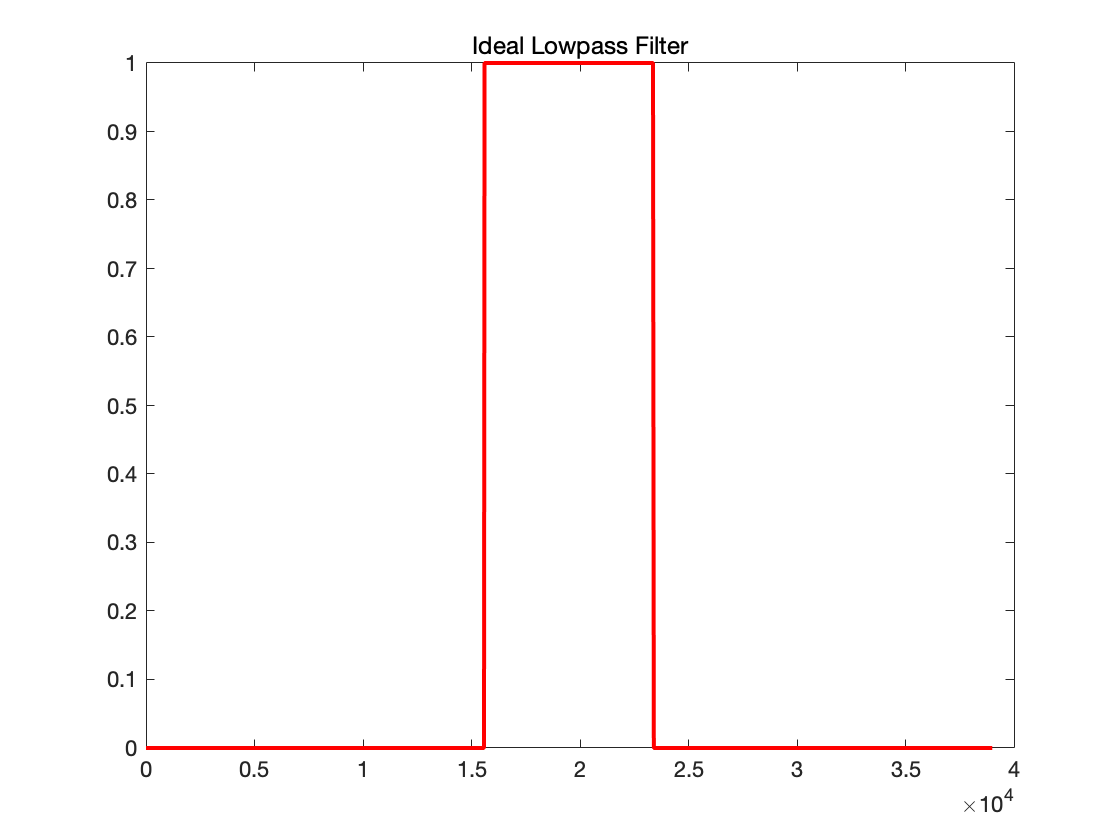

lpf = [zeros(1,15600) ones(1,7801) zeros(1,15599)];
figure
plot(lpf,'r',"linewidth",2),title('Ideal Lowpass Filter')


cos_sig = cos(wc*uut);
sin_sig = sin(wc*uut);
Xr_without_lpf = data1_with_h.*cos_sig;
Xi_without_lpf = data1_with_h.*sin_sig;
Xr_with_lpf = 2*fftshift(fft(Xr_without_lpf)).*lpf;
Xi_with_lpf = 2*fftshift(fft(Xi_without_lpf)).*lpf;
data1_after_dem = ifft(fftshift(Xr_with_lpf)) + i*ifft(fftshift(Xi_with_lpf));

Xr2_without_lpf = data2_with_h.*cos_sig;
Xi2_without_lpf = data2_with_h.*sin_sig;
Xr2_with_lpf = 2*fftshift(fft(Xr2_without_lpf)).*lpf;
Xi2_with_lpf = 2*fftshift(fft(Xi2_without_lpf)).*lpf;
data2_after_dem = ifft(fftshift(Xr2_with_lpf)) + i*ifft(fftshift(Xi2_with_lpf));
%-----------------------------------------------------------
figure
subplot(1,2,1);
%plot(uut,conv(data1_c,ht))
plot(uut, data1_after_dem);xlabel('t');ylabel('data1_after_demodulation');

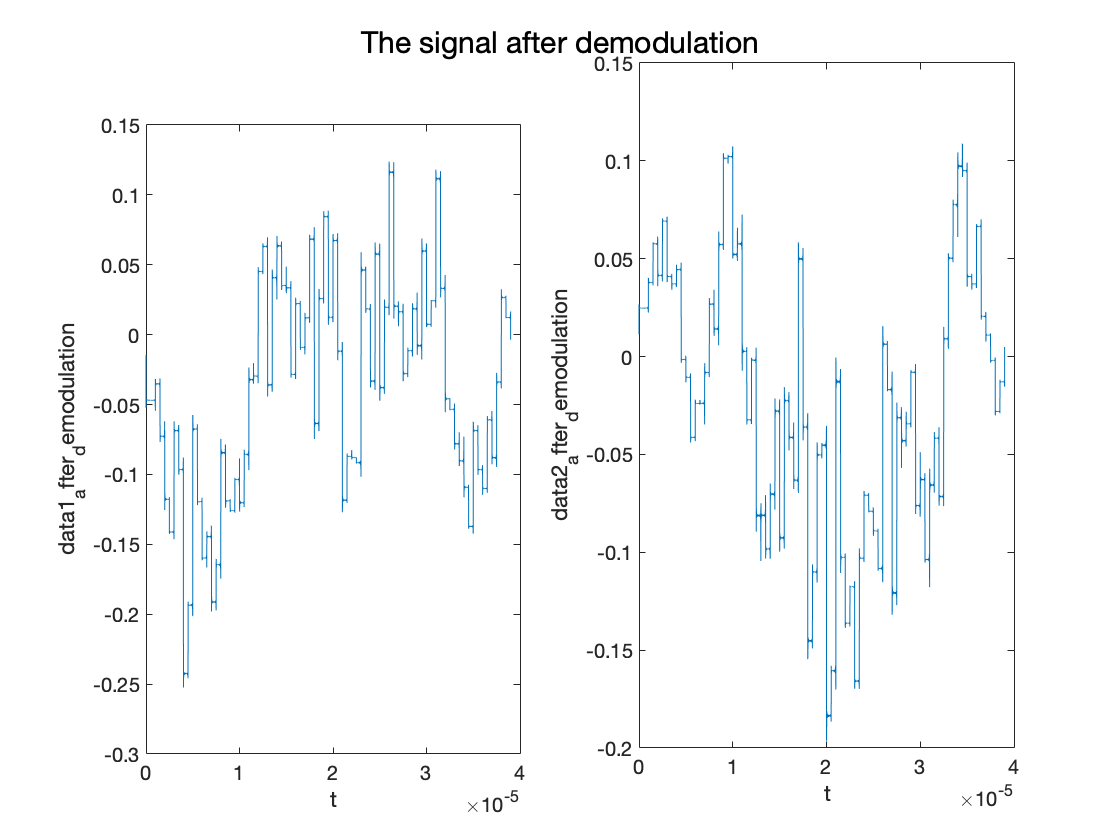

suptitle('The signal after demodulation')
subplot(1,2,2);
plot(uut, data2_after_dem);xlabel('t');ylabel('data2_after_demodulation');

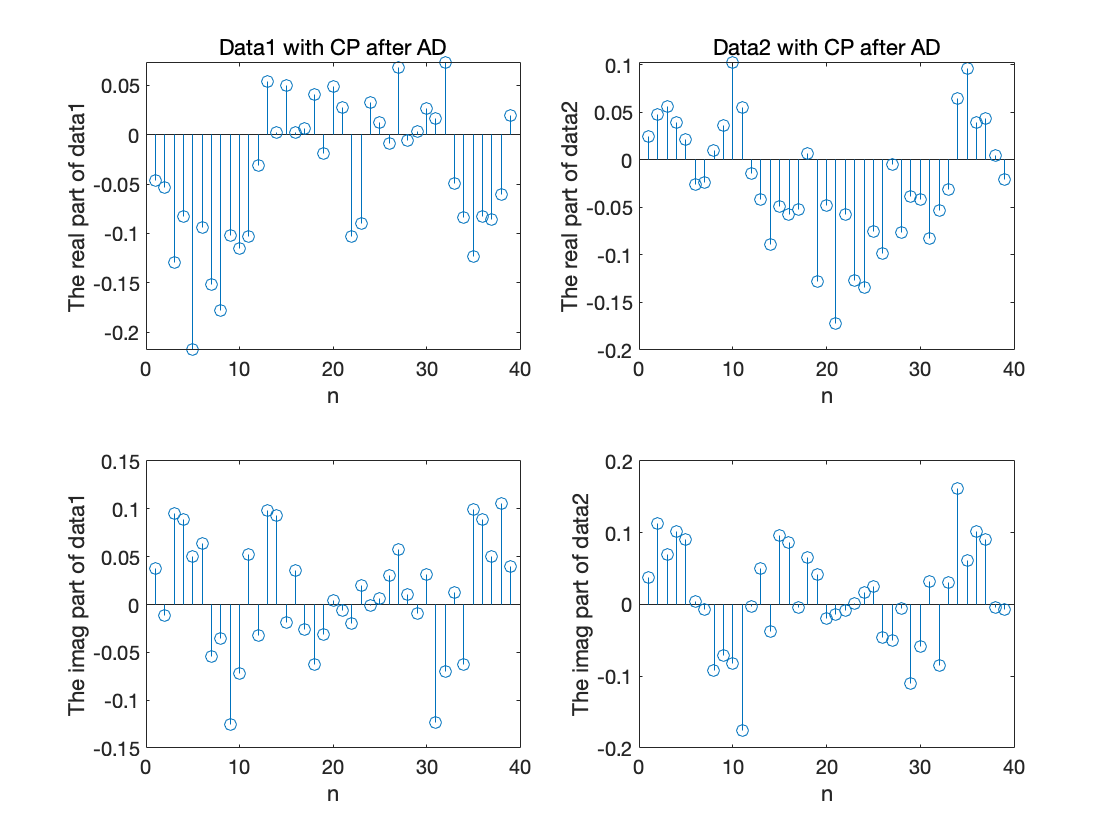

A = reshape(data1_after_dem,1000,[]);
data1_after_AD = mean(A,1);
B = reshape(data2_after_dem,1000,[]);
data2_after_AD = mean(B,1);
%-----------------------------------------------
figure

subplot(2,2,1);
stem(real(data1_after_AD));xlabel('n');ylabel('The real part of data1');title('Data1 with CP after AD')
subplot(2,2,3);
stem(imag(data1_after_AD));xlabel('n');ylabel('The imag part of data1');
subplot(2,2,2);
stem(real(data2_after_AD));xlabel('n');ylabel('The real part of data2');title('Data2 with CP after AD')
subplot(2,2,4);
stem(imag(data2_after_AD));xlabel('n');ylabel('The imag part of data2');

### Block 2

%去除cp以及经过信道产生的无效的信号
data1_without_cp = data1_after_AD(5:length(data1_after_AD)-3);
data2_without_cp = data2_after_AD(5:length(data2_after_AD)-3);
figure
subplot(211)
stem(data1_without_cp),title("data1 without cp");

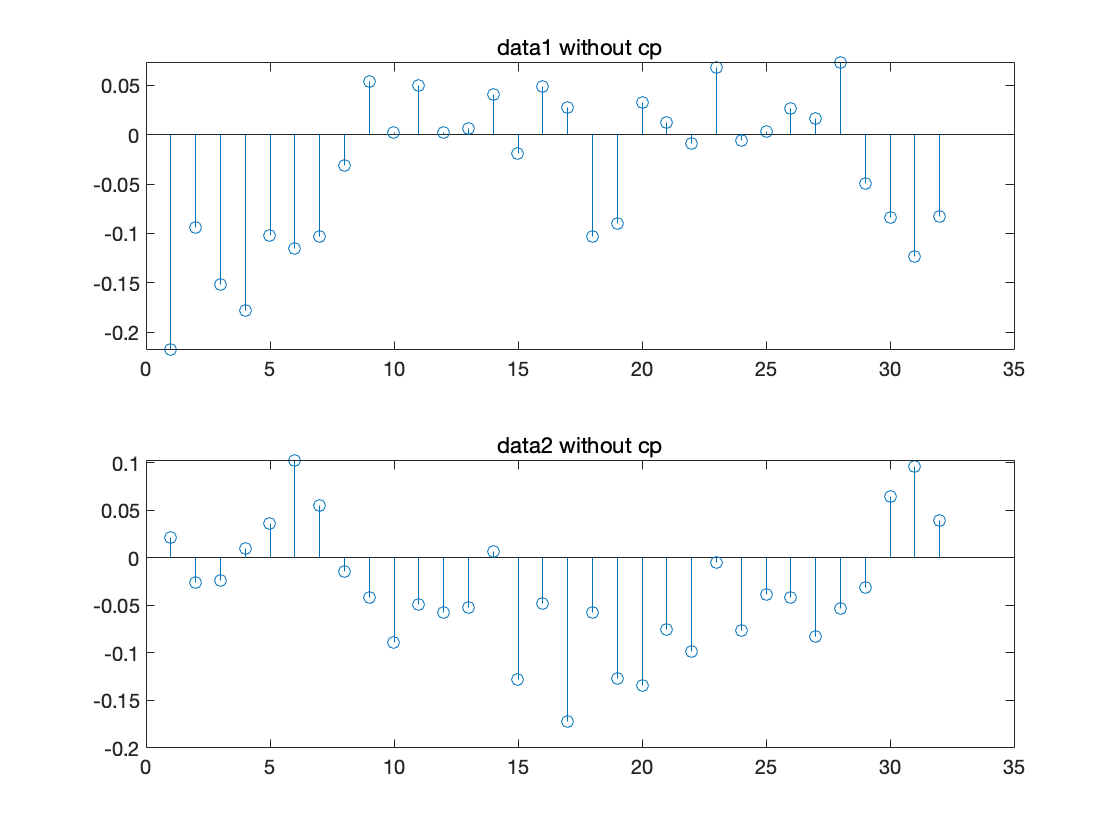

subplot(212)
stem(data2_without_cp),title("data2 without cp");


%由ak求解Hk
%构建一个已知的计算函数tone经过以上处理步骤用于计算H
tone = [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1];
tone1 = tone';
Tone = ifft(tone1);
tone11 = Tone';
tone_cp = [tone11(end-3:end),tone11];
tone_cc = repmat(tone_cp,1000,1);
tone_c = reshape(tone_cc,1,[]);
tone_with_h = conv(tone_c,ht);
% C = reshape(tone_with_h,1000,[]);
% tone_AD = mean(A,1);
int = [];
for i = [1:39]
    m = tone_with_h(i*1000-999:i*1000);
    int = [int sum(m)];    
end
tone_AD = int/1000;
tone_without_cp = tone_AD(5:length(tone_AD)-3);
Tone_without_cp = tone_without_cp';

Tone_k = fft(Tone_without_cp)/32;
tone_k = Tone_k';
H = tone_k./(tone*32);  %
figure
stem(1:32,H);xlabel('n');ylabel('H[n]');

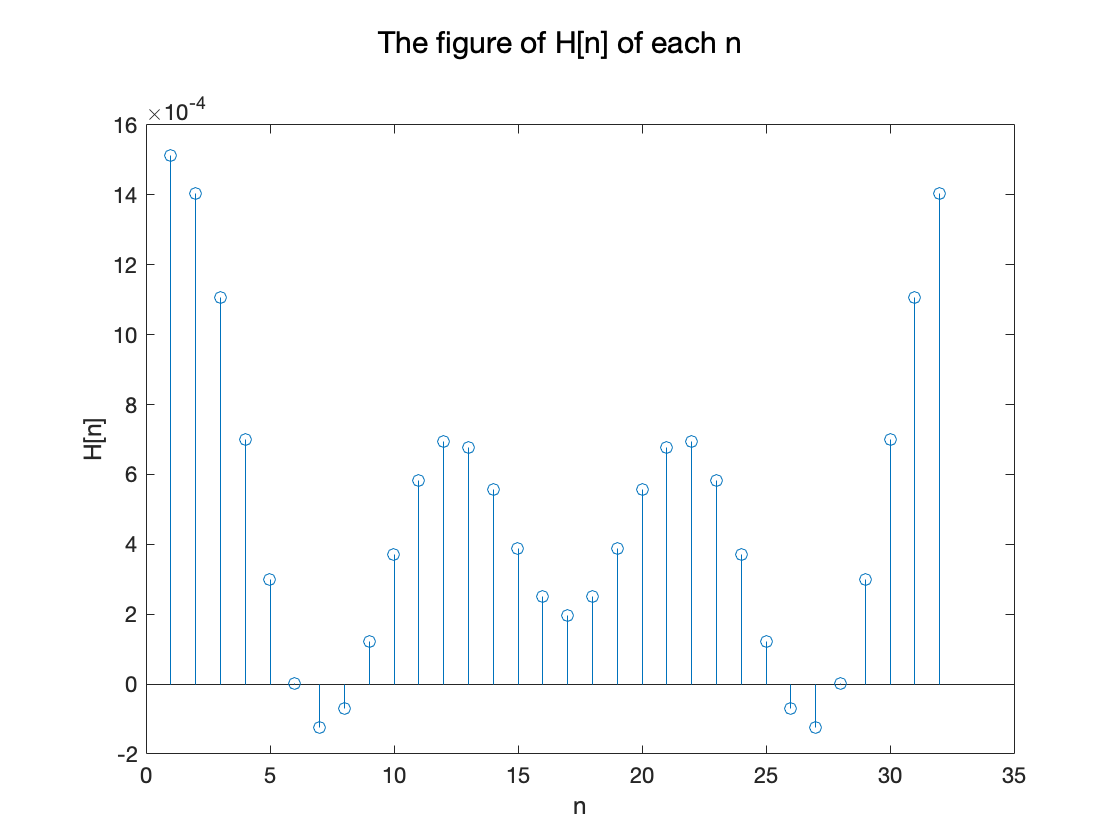

suptitle('The figure of H[n] of each n');

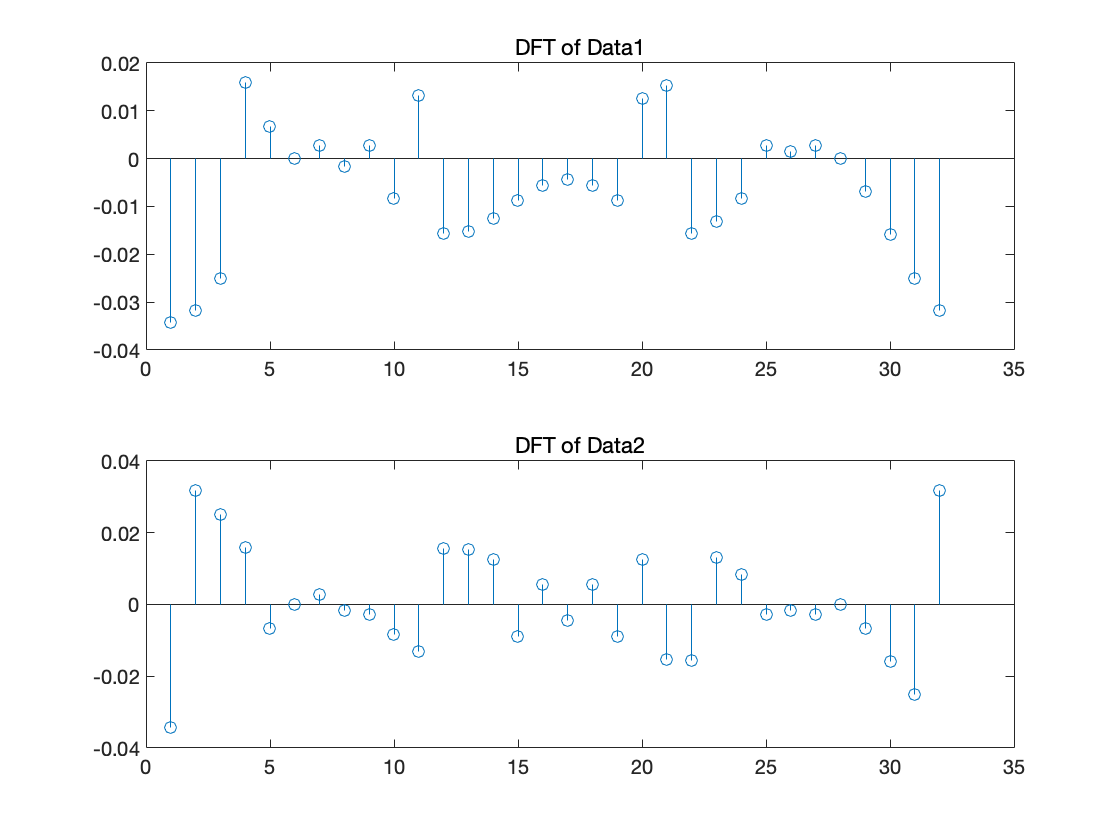


data1_without_cp = data1_without_cp';
Data1_k = fft(data1_without_cp)/32;
Data1_k = Data1_k';
data1_re = Data1_k./H/32;

data2_without_cp = data2_without_cp';
Data2_k = fft(data2_without_cp)/32;
Data2_k = Data2_k';
data2_re = Data2_k./H/32;

figure
subplot(211)
stem(real(Data1_k)),title("DFT of Data1");
subplot(212)
stem(real(Data2_k)),title("DFT of Data2");

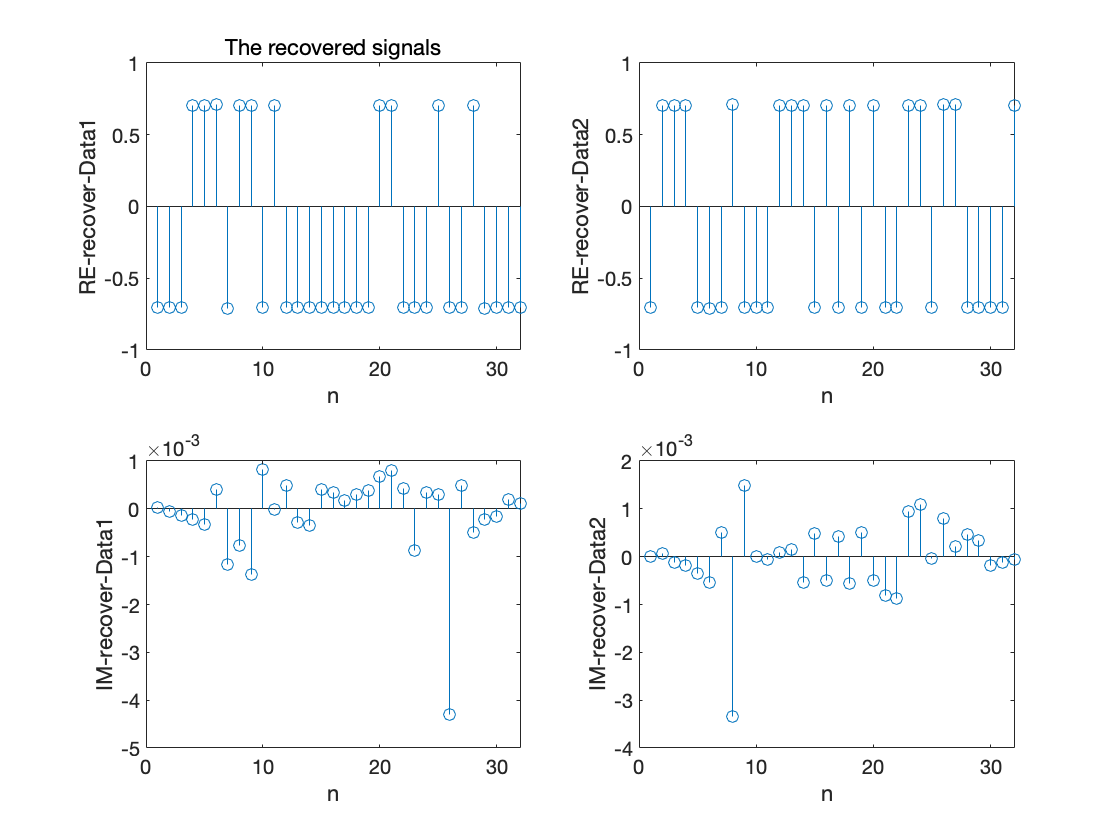


figure
subplot(2,2,1);
stem(1:N,real(data1_re));xlabel('n');ylabel('RE-recover-Data1');title('The recovered signals')
subplot(2,2,3);
stem(1:N,imag(data1_re));xlabel('n');ylabel('IM-recover-Data1');
subplot(2,2,2);
stem(1:N,real(data2_re));xlabel('n');ylabel('RE-recover-Data2');
subplot(2,2,4);
stem(1:N,imag(data2_re));xlabel('n');ylabel('IM-recover-Data2');

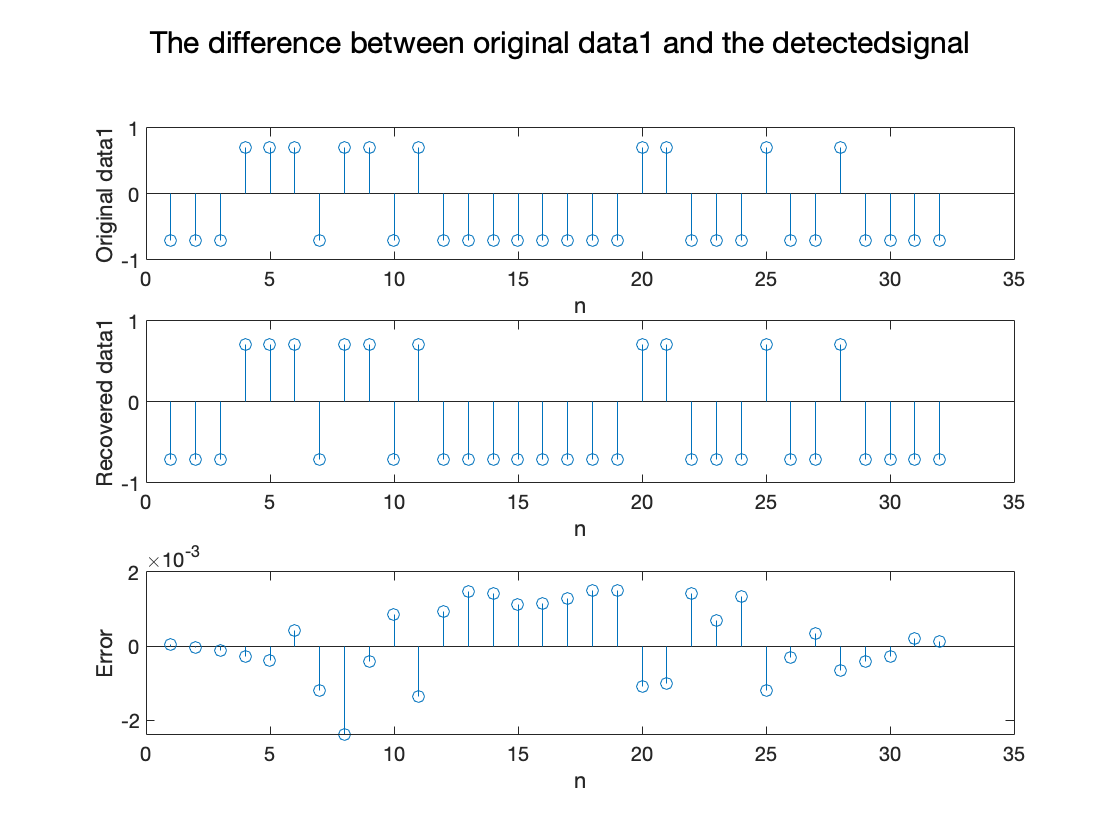


%-----------------------------------------------------
%对比原信号以及恢复信号
figure
subplot(3,1,1);
stem(1:N,data1_ori);xlabel('n');ylabel('Original data1');
suptitle('The difference between original data1 and the detectedsignal');
subplot(3,1,2);
stem(1:N,real(data1_re));xlabel('n');ylabel('Recovered data1');
subplot(3,1,3);
stem(1:N,real(data1_re)-data1_ori);xlabel('n');ylabel('Error');

maxerror1 = max(abs(data1_ori-real(data1_re))/abs(data1_ori))*100

maxerror1 = 0.1188

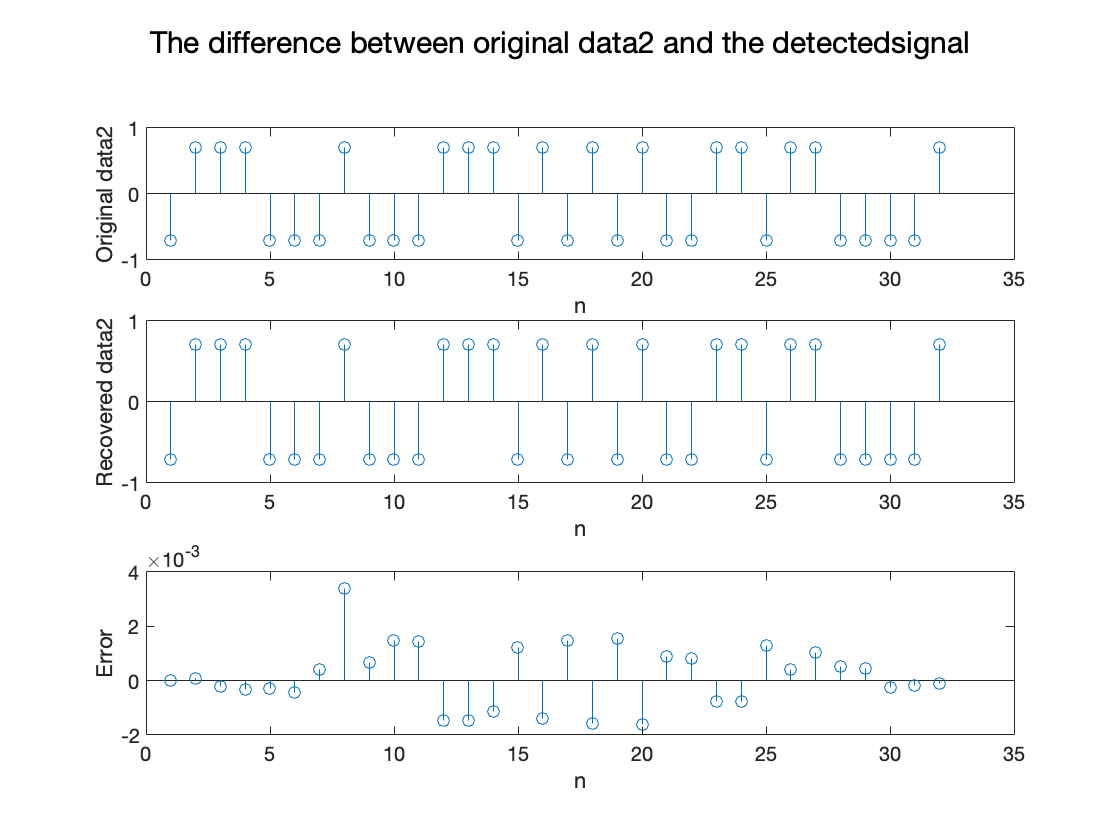


figure
subplot(3,1,1);
stem(1:N,data2_ori);xlabel('n');ylabel('Original data2');
suptitle('The difference between original data2 and the detectedsignal');
subplot(3,1,2);
stem(1:N,real(data2_re));xlabel('n');ylabel('Recovered data2');
subplot(3,1,3);
stem(1:N,real(data2_re)-data2_ori);xlabel('n');ylabel('Error');

maxerror2 = max(abs(data2_ori-real(data2_re))/abs(data2_ori))*100

maxerror2 = 0.1287

结论：误差均小于5%，检验成立

figure("Name",'信道响应')
subplot(211)
stem(0:length(H)-1,real(H));grid on;xlabel('n');ylabel('Magnitude');title('Real(Correction Function of H[n]');
subplot(212)
stem(0:length(H)-1,imag(H));grid on;xlabel('n');ylabel('Magnitude');title('Imag(Correction Function of H[n]');